# Machine Learning: Programming Exercise 3

## Multi-class Classification and Neural Networks

In this exercise, you will implement one-vs-all logistic regression and neural networks to recognize hand-written digits.

### Files needed for this exercise

- `ex3.mlx` - MATLAB Live Script that steps you through the exercise

- `ex3data1.mat` - Training set of hand-written digits

- `ex3weights.mat` - Initial weights for the neural network exercise

- `submit.m `- Submission script that sends your solutions to our servers

- `displayData.m` - Function to help visualize the dataset

- `fmincg.m` - Function minimization routine (similar to `fminunc`)

- `sigmoid.m` - Sigmoid function

- `*lrCostFunction.m` - Logistic regression cost function

- `*oneVsAll.m` - Train a one-vs-all multi-class classifier

- `*predictOneVsAll.m` - Predict using a one-vs-all multi-class classifier

- `*predict.m `- Neural network prediction function

****indicates files you will need to complete***

#### Clear existing variables and confirm that your Current Folder is set correctly

Click into this section, then click the 'Run Section' button above. This will execute the `clear` command to clear existing variables and the `dir` command to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex3' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

clear
dir

.                  ex3_companion.mat  fmincg.m           predict.asv        submit.m           
..                 ex3_companion.mlx  lib                predict.m          token.mat          
displayData.m      ex3data1.mat       lrCostFunction.m   predictOneVsAll.m  
ex3.mlx            ex3weights.mat     oneVsAll.m         sigmoid.m          



### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README` and have checked for an existing solution before seeking help on the discussion forums.

## 1. Multi-class Classification

For this exercise, you will use logistic regression and neural networks to recognize handwritten digits (from 0 to 9). Automated handwritten digit recognition is widely used today - from recognizing zip codes (postal codes) on mail envelopes to recognizing amounts written on bank checks. This exercise will show you how the methods you've learned can be used for this classication task. In the first part of the exercise, you will extend your previous implemention of logistic regression and apply it to one-vs-all classification.

### 1.1 Dataset

You are given a data set in `ex3data1.mat` that contains 5000 training examples of handwritten digits*. The .mat format means that that the data has been saved in a native MATLAB matrix format, instead of a text (ASCII) format like a csv-file. These matrices can be read directly into your program by using the load command. After loading, matrices of the correct dimensions and values will appear in your program's memory. The matrix will already be named, so you do not need to assign names to them. 

**This is a subset of the MNIST *[*handwritten digit dataset*](http://yann.lecun.com/exdb/mnist/)

Run the code below to load the data.

% Load saved matrices from file
load('ex3data1.mat');
% The matrices X and y will now be in your MATLAB environment

    There are 5000 training examples in `ex3data1.mat`, where each training example is a 20 pixel by 20 pixel grayscale image of the digit. Each pixel is represented by a floating point number indicating the grayscale intensity at that location. The 20 by 20 grid of pixels is 'unrolled' into a 400-dimensional vector. Each of these training examples becomes a single row in our data matrix `X`. This gives us a 5000 by 400 matrix `X` where every row is a training example for a handwritten digit image.


$$X=\left\lbrack \begin{array}{c}
-{\left(x^{\left(1\right)} \right)}^T -\\
-{\left(x^{\left(2\right)} \right)}^T -\\
\vdots \\
-{\left(x^{\left(m\right)} \right)}^T -
\end{array}\right\rbrack$$


    The second part of the training set is a 5000-dimensional vector `y` that contains labels for the training set. To make things more compatible with MATLAB indexing, where there is no zero index, we have mapped the digit zero to the value ten. Therefore, a '0' digit is labeled as '10', while the digits '1' to '9' are labeled as '1' to '9' in their natural order.

## 1.2 Visualizing the data

You will begin by visualizing a subset of the training set. The code below randomly selects selects 100 rows from `X` and passes those rows to the `displayData` function. This function maps each row to a 20 pixel by 20 pixel grayscale image and displays the images together. We have provided the `displayData` function, and you are encouraged to examine the code to see how it works. After you run this step, you should see an image like Figure 1.

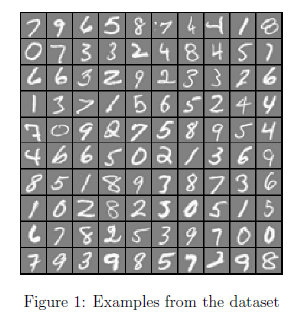                        

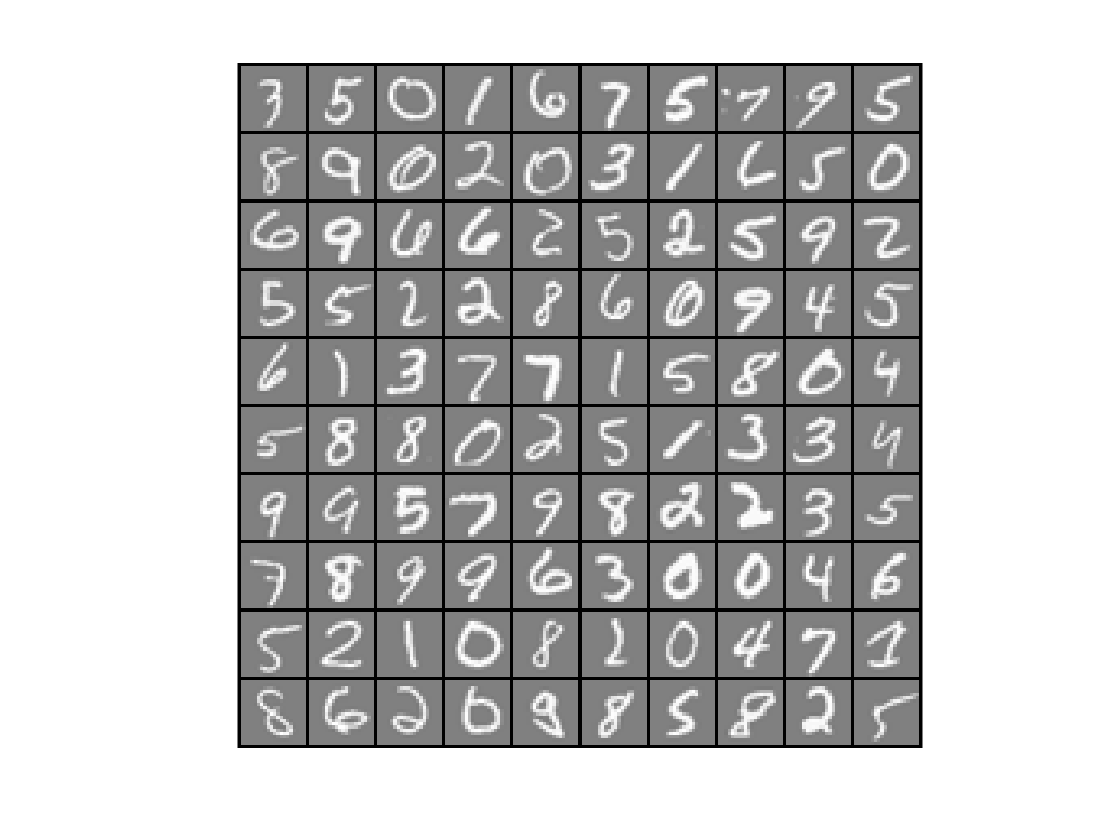

m = size(X, 1);
% Randomly select 100 data points to display
rand_indices = randperm(m);
sel = X(rand_indices(1:100), :);
displayData(sel);

### 1.3 Vectorizing logistic regression

You will be using multiple one-vs-all logistic regression models to build a multi-class classifier. Since there are 10 classes, you will need to train 10 separate logistic regression classifiers. To make this training efficient, it is important to ensure that your code is well vectorized. In this section, you will implement a vectorized version of logistic regression that does not employ any `for` loops. You can use your code in the last exercise as a starting point for this exercise.

#### 1.3.1 Vectorizing the cost function

We will begin by writing a vectorized version of the cost function. Recall that in (unregularized) logistic regression, the cost function is


$$J(\theta) =\frac{1}{m}\sum_{i=1}^m{\left[

-y^{(i)} \log(h_{\theta}(x^{(i)}))- (1-y^{(i)}) \log(1- h_{\theta}(x^{(i)}))\right],$$


To compute each element in the summation, we have to compute $h_{\theta}(x^{(i)})$ for every example $i$, where $h_{\theta}(x^{(i)}) = g(\theta^T x^{(i)})$ and $g(z) =\frac{1}{1+e^{-z}}$ is the sigmoid function. It turns out that we can compute this quickly for all our examples by using matrix multiplication. Let us define $X$ and $\theta$ as


$$X\theta \;=\left\lbrack \begin{array}{c}
-{\left(x^{\left(1\right)} \right)}^T \theta \;-\\
-{\left(x^{\left(2\right)} \right)}^T \theta \;-\\
\vdots \\
-{\left(x^{\left(m\right)} \right)}^T \theta \;-
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-\;\theta^T \left(x^{\left(1\right)} \right)-\\
-{\;\theta }^T \left(x^{\left(2\right)} \right)\;-\\
\vdots \\
-{\;\theta }^T \left(x^{\left(m\right)} \right)-
\end{array}\right\rbrack \;$$


In the last equality, we used the fact that $a^T b= b^T a$ if $a$ and $b$ are vectors. This allows us to compute the products $\theta^T x^{(i)}$ for all our examples $i$ in one line of code.

    Your job is to write the unregularized cost function in the file `lrCostFunction.m `Your implementation should use the strategy we presented above to calculate $\theta^T x^{(i)}$. You should also use a vectorized approach for the rest of the cost function. A fully vectorized version of `lrCostFunction.m` should not contain any loops. (Hint: You might want to use the element-wise multiplication operation (`.*`) and the sum operation `sum` when writing this function)

#### 1.3.2 Vectorizing the gradient

Recall that the gradient of the (unregularized) logistic regression cost is a vector where the $j$th element is defined as 


$$\frac{\partial J(\theta)}{\partial \theta_j} = \frac{1}{m}\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_j^{(i)}
$$


To vectorize this operation over the dataset, we start by writing out all the partial derivatives explicitly for all $\theta_j$,

$\left[ \begin{array}{c} 
\frac{\partial J(\theta)}{\partial \theta_0} \\
\frac{\partial J(\theta)}{\partial \theta_1} \\
\frac{\partial J(\theta)}{\partial \theta_2} \\
\vdots \\
\frac{\partial J(\theta)}{\partial \theta_n}   
 \end{array} \right]
 = \frac{1}{m}
\left[ \begin{array}{c} 
\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_0^{(i)} \\
\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_1^{(i)} \\
\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_2^{(i)} \\
\vdots \\
\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_n^{(i)}
\end{array}\right] =\frac{1}{m} \sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x^{(i)} =
\frac{1}{m}X^T {\left( h_\theta(x)-y\right)}
$   (1)

where


$$h_{\theta \;} \left(x\right)-y=\left\lbrack \begin{array}{c}
h_{\theta \;} \left(x^{\left(1\right)} \right)-y^{\left(1\right)} \\
h_{\theta \;} \left(x^{\left(2\right)} \right)-y^{\left(2\right)} \\
\vdots \\
h_{\theta \;} \left(x^{\left(m\right)} \right)-y^{\left(m\right)} 
\end{array}\right\rbrack$$


    Note that $x^{(i)}$ is a vector, while $(h_\theta(x^{(i)})-y^{(i)})$ is a scalar (single number). To understand the last step of the derivation, let $\beta_i = (h_\theta(x^{(i)})-y^{(i)})$ and observe that:


$$\sum_i \beta_i x^{\left(i\right)} =\left\lbrack \begin{array}{cccc}
| & | & \; & |\\
x^{\left(1\right)}  & x^{\left(2\right)}  & \dots  & x^{\left(m\right)} \\
| & | & \; & |
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\beta_1 \\
\beta_2 \\
\vdots \\
\beta_m 
\end{array}\right\rbrack =X^T \beta ,$$


    The expression above allows us to compute all the partial derivatives without any loops. If you are comfortable with linear algebra, we encourage you to work through the matrix multiplications above to convince yourself that the vectorized version does the same computations. You should now implement Equation (1) to compute the correct vectorized gradient. Once you are done, complete the function `lrCostFunction.m` by implementing the gradient.

**Debugging Tip: **Vectorizing code can sometimes be tricky. One common strategy for debugging is to print out the sizes of the matrices you are working with using the size function. For example, given a data matrix $X$ of size 100 x 20 (100 examples, 20 features) and $\theta$, a vector with dimensions 20 x 1, you can observe that $X\theta$ is a valid multiplication operation, while $\theta X$ is not. Furthermore, if you have a non-vectorized version of your code, you can compare the output of your vectorized code and non-vectorized code to make sure that they produce the same outputs.

#### 1.3.3 Vectorizing regularized logistic regression

After you have implemented vectorization for logistic regression, you will now add regularization to the cost function. Recall that for regularized logistic regression, the cost function is defined as


$$J(\theta) =\frac{1}{m}\sum_{i=1}^m{\left[

-y^{(i)} \log(h_{\theta}(x^{(i)}))- (1 -y^{(i)}) \log(1-h_{\theta}(x^{(i)}))\right]+\frac{\lambda}{2m}\sum_{j=1}^n{\theta_j^2}$$


Note that you should not be regularizing $\theta_0$ which is used for the bias term. Correspondingly, the partial derivative of regularized logistic regression cost for $\theta_j$ is defined as


$$\frac{\partial J(\theta)}{\partial \theta_j} = \frac{1}{m}\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_j^{(i)}\qquad \mathrm{for}\;j=0,
$$



$$\frac{\partial J(\theta)}{\partial \theta_j} = \left( \frac{1}{m}\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_j^{(i)}} \right)+\frac{\lambda}{m}\theta_j\qquad \mathrm{for}\;j\geq1$$


Now modify your code in `lrCostFunction` to account for regularization. Once again, you should not put any loops into your code. When you are finished, run the code below to test your vectorized implementation and compare to expected outputs:

theta_t = [-2; -1; 1; 2];
X_t = [ones(5,1) reshape(1:15,5,3)/10];
y_t = ([1;0;1;0;1] >= 0.5);
lambda_t = 3;
[J, grad] = lrCostFunction(theta_t, X_t, y_t, lambda_t);

thetaZero =     -2
    -1
     1
     2



fprintf('Cost: %f | Expected cost: 2.534819\n',J);

Cost: 2.534819 | Expected cost: 2.534819


fprintf('Gradients:\n'); fprintf('%f\n',grad);

Gradients:
0.146561
-0.548558
0.724722
1.398003


fprintf('Expected gradients:\n 0.146561\n -0.548558\n 0.724722\n 1.398003');

Expected gradients:
 0.146561
 -0.548558
 0.724722
 1.398003

**MATLAB Tip:** When implementing the vectorization for regularized logistic regression, you might often want to only sum and update certain elements of $\theta$. In MATLAB, you can index into the matrices to access and update only certain elements. For example, `A(:,3:5)= B(:, 1:3)` will replace columns 3 to 5 of `A` with the columns 1 to 3 from `B`. One special keyword you can use in indexing is the `end` keyword in indexing. This allows us to select columns (or rows) until the end of the matrix. For example, `A(:, 2:end)` will only return elements from the 2nd to last column of `A`. Thus, you could use this together with the `sum` and `.^` operations to compute the sum of only the elements you are interested in (e.g. `sum(z(2:end).^2))`. In the starter code,` lrCostFunction.m`, we have also provided hints on yet another possible method computing the regularized gradient.

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 1.4 One-vs-all classication

In this part of the exercise, you will implement one-vs-all classification by training multiple regularized logistic regression classifiers, one for each of the $K$ classes in our dataset (Figure 1). In the handwritten digits dataset, $K = 10$, but your code should work for any value of $K$. 

    You should now complete the code in `oneVsAll.m` to train one classifier for each class. In particular, your code should return all the classifier parameters in a matrix $\Theta \in \mathbb{R}^{K\times(N+1)}$, where each row of $\Theta$ corresponds to the learned logistic regression parameters for one class. You can do this with a `for` loop from 1 to `K`, training each classifier independently.

Note that the `y` argument to this function is a vector of labels from 1 to 10, where we have mapped the digit '0' to the label 10 (to avoid confusions with indexing). When training the classifier for class $k \in \{1,\ldots,K\},$ you will want a $m$-dimensional vector of labels $y,$ where $y_j\in \{0,\;1\}$ indicates whether the $j$-th training instance belongs to class $k\; (y_j = 1)$, or if it belongs to a different class $(y_j = 0).$ You may find logical arrays helpful for this task.

**MATLAB Tip**: Logical arrays in MATLAB are arrays which contain binary (0 or 1) elements. In MATLAB, evaluating the expression `a == b` for a vector `a` (of size $m\times1$) and scalar `b` will return a vector of the same size as `a` with ones at positions where the elements of `a` are equal to `b` and zeroes where they are different. To see how this works for yourself, run the following code:

a = 1:10; % Create a and b
b = 3;
disp(a == b) % You should try different values of b here

   0   0   1   0   0   0   0   0   0   0



Furthermore, you will be using `fmincg` for this exercise (instead of `fminunc`). `fmincg` works similarly to `fminunc`, but is more more efficient for dealing with a large number of parameters. After you have correctly completed the code for `oneVsAll.m`, run the code below to use your `oneVsAll` function to train a multi-class classifier.

num_labels = 10; % 10 labels, from 1 to 10 
lambda = 0.1;
[all_theta] = oneVsAll(X, y, num_labels, lambda);

thetaZero =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


thetaZero =    -0.0872
         0
         0
    0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


Iteration     1 | Cost: 2.802128e-01


thetaZero =    -0.1010
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0002
   -0.0001
    0.0001
   -0.0001


Iteration     2 | Cost: 9.454389e-02


thetaZero =    -1.0978
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0002
   -0.0002
    0.0001
   -0.0001


thetaZero =    -0.3073
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0002
   -0.0001
    0.0001
   -0.0001


thetaZero =    -0.2050
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0002
   -0.0001
    0.0001
   -0.0001


Iteration     3 | Cost: 5.704641e-02


thetaZero =    -0.1309
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0002
    0.0001
    0.0008
   -0.0001


thetaZero =    -0.1771
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0002
   -0.0000
    0.0003
   -0.0001


Iteration     4 | Cost: 4.688190e-02


thetaZero =    -0.2706
         0
         0
    0.0000
   -0.0000
   -0.0001
   -0.0002
    0.0005
    0.0018
   -0.0002


Iteration     5 | Cost: 3.759021e-02


thetaZero =    -0.1540
         0
         0
    0.0000
   -0.0001
   -0.0001
   -0.0003
    0.0009
    0.0031
   -0.0002


thetaZero =    -0.2473
         0
         0
    0.0000
   -0.0001
   -0.0001
   -0.0002
    0.0006
    0.0021
   -0.0002


Iteration     6 | Cost: 3.522008e-02


thetaZero =    -0.4419
         0
         0
    0.0000
   -0.0001
   -0.0001
   -0.0003
    0.0006
    0.0027
   -0.0002


Iteration     7 | Cost: 3.234531e-02


thetaZero =    -0.6116
         0
         0
    0.0000
   -0.0001
   -0.0001
   -0.0002
    0.0002
    0.0029
   -0.0001


thetaZero =    -0.4931
         0
         0
    0.0000
   -0.0001
   -0.0001
   -0.0002
    0.0005
    0.0027
   -0.0002


Iteration     8 | Cost: 3.145034e-02


thetaZero =    -0.6000
         0
         0
    0.0000
   -0.0001
   -0.0001
   -0.0002
    0.0003
    0.0028
   -0.0001


Iteration     9 | Cost: 3.008919e-02


thetaZero =    -0.6404
         0
         0
    0.0000
   -0.0001
   -0.0001
   -0.0002
    0.0003
    0.0027
   -0.0001


thetaZero =    -0.6060
         0
         0
    0.0000
   -0.0001
   -0.0001
   -0.0002
    0.0003
    0.0028
   -0.0001


Iteration    10 | Cost: 2.994639e-02


thetaZero =    -0.6256
         0
         0
    0.0000
   -0.0001
   -0.0001
   -0.0002
    0.0003
    0.0027
   -0.0001


thetaZero =    -0.6649
         0
         0
    0.0000
   -0.0001
   -0.0001
   -0.0002
    0.0002
    0.0027
   -0.0001


thetaZero =    -0.7827
         0
         0
    0.0000
   -0.0001
   -0.0001
   -0.0002
   -0.0000
    0.0027
   -0.0001


thetaZero =    -1.0203
         0
         0
    0.0000
   -0.0001
   -0.0001
   -0.0002
   -0.0005
    0.0026
   -0.0001


Iteration    11 | Cost: 2.678528e-02


thetaZero =    -1.7993
         0
         0
    0.0000
   -0.0001
   -0.0001
   -0.0000
   -0.0019
    0.0022
   -0.0000


thetaZero =    -1.0982
         0
         0
    0.0000
   -0.0001
   -0.0001
   -0.0001
   -0.0006
    0.0025
   -0.0001


thetaZero =    -1.0689
         0
         0
    0.0000
   -0.0001
   -0.0001
   -0.0002
   -0.0006
    0.0025
   -0.0001


Iteration    12 | Cost: 2.660323e-02


thetaZero =    -1.1066
         0
         0
    0.0000
   -0.0001
   -0.0001
   -0.0001
   -0.0007
    0.0025
   -0.0001


thetaZero =    -1.1821
         0
         0
    0.0000
   -0.0001
   -0.0001
   -0.0001
   -0.0009
    0.0025
   -0.0001


thetaZero =    -1.4086
         0
         0
    0.0000
   -0.0001
   -0.0001
   -0.0001
   -0.0014
    0.0023
   -0.0000


Iteration    13 | Cost: 2.493301e-02


thetaZero =    -1.9956
         0
         0
    0.0000
   -0.0001
   -0.0002
    0.0000
   -0.0028
    0.0020
    0.0000


thetaZero =    -1.4744
         0
         0
    0.0000
   -0.0001
   -0.0001
   -0.0001
   -0.0016
    0.0023
   -0.0000


Iteration    14 | Cost: 2.475211e-02


thetaZero =    -1.5348
         0
         0
    0.0000
   -0.0001
   -0.0001
   -0.0000
   -0.0018
    0.0022
   -0.0000


thetaZero =    -1.6556
         0
         0
    0.0000
   -0.0001
   -0.0001
   -0.0000
   -0.0021
    0.0022
   -0.0000


thetaZero =    -2.0156
         0
         0
    0.0000
   -0.0002
   -0.0002
    0.0001
   -0.0032
    0.0019
    0.0000


Iteration    15 | Cost: 2.318421e-02


thetaZero =    -2.6574
         0
         0
    0.0000
   -0.0002
   -0.0002
    0.0002
   -0.0049
    0.0016
    0.0001


thetaZero =    -2.1464
         0
         0
    0.0000
   -0.0002
   -0.0002
    0.0001
   -0.0035
    0.0019
    0.0001


Iteration    16 | Cost: 2.287050e-02


thetaZero =    -2.2684
         0
         0
    0.0000
   -0.0002
   -0.0002
    0.0001
   -0.0039
    0.0018
    0.0001


thetaZero =    -2.5123
         0
         0
    0.0000
   -0.0002
   -0.0002
    0.0002
   -0.0046
    0.0017
    0.0001


Iteration    17 | Cost: 2.160258e-02


thetaZero =    -2.3921
         0
         0
    0.0000
   -0.0002
   -0.0002
    0.0002
   -0.0044
    0.0018
    0.0001


thetaZero =    -2.4625
         0
         0
    0.0000
   -0.0002
   -0.0002
    0.0002
   -0.0045
    0.0018
    0.0001


Iteration    18 | Cost: 2.120371e-02


thetaZero =    -2.4413
         0
         0
    0.0000
   -0.0002
   -0.0002
    0.0002
   -0.0044
    0.0018
    0.0001


Iteration    19 | Cost: 2.064125e-02


thetaZero =    -2.5089
         0
         0
    0.0000
   -0.0002
   -0.0002
    0.0002
   -0.0046
    0.0018
    0.0001


thetaZero =    -2.4537
         0
         0
    0.0000
   -0.0002
   -0.0002
    0.0002
   -0.0045
    0.0018
    0.0001


Iteration    20 | Cost: 2.055695e-02


thetaZero =    -2.4516
         0
         0
    0.0000
   -0.0002
   -0.0002
    0.0002
   -0.0045
    0.0018
    0.0001


Iteration    21 | Cost: 2.045466e-02


thetaZero =    -2.4594
         0
         0
    0.0000
   -0.0002
   -0.0002
    0.0002
   -0.0045
    0.0018
    0.0001


thetaZero =    -2.4683
         0
         0
    0.0000
   -0.0002
   -0.0002
    0.0002
   -0.0045
    0.0018
    0.0001


Iteration    22 | Cost: 2.029177e-02


thetaZero =    -2.4771
         0
         0
    0.0000
   -0.0002
   -0.0002
    0.0002
   -0.0046
    0.0018
    0.0001


Iteration    23 | Cost: 2.005296e-02


thetaZero =    -2.4637
         0
         0
    0.0000
   -0.0002
   -0.0002
    0.0002
   -0.0046
    0.0019
    0.0001


thetaZero =    -2.4694
         0
         0
    0.0000
   -0.0002
   -0.0002
    0.0002
   -0.0046
    0.0018
    0.0001


Iteration    24 | Cost: 1.995949e-02


thetaZero =    -2.4750
         0
         0
    0.0000
   -0.0002
   -0.0002
    0.0002
   -0.0046
    0.0019
    0.0001


Iteration    25 | Cost: 1.982849e-02


thetaZero =    -2.4906
         0
         0
    0.0000
   -0.0002
   -0.0002
    0.0002
   -0.0047
    0.0019
    0.0001


Iteration    26 | Cost: 1.975129e-02


thetaZero = 401×1
   -2.4950
         0
         0
    0.0000
   -0.0002
   -0.0003
    0.0002
   -0.0048
    0.0019
    0.0001


thetaZero = 401×1
   -2.5040
         0
         0
    0.0000
   -0.0002
   -0.0003
    0.0002
   -0.0050
    0.0019
    0.0001


thetaZero = 401×1
   -2.5282
         0
         0
    0.0000
   -0.0003
   -0.0003
    0.0003
   -0.0055
    0.0019
    0.0001


Iteration    27 | Cost: 1.897815e-02


thetaZero = 401×1
   -2.6787
         0
         0
    0.0000
   -0.0004
   -0.0004
    0.0004
   -0.0070
    0.0020
    0.0001


thetaZero = 401×1
   -2.5516
         0
         0
    0.0000
   -0.0003
   -0.0003
    0.0003
   -0.0057
    0.0019
    0.0001


Iteration    28 | Cost: 1.887065e-02


thetaZero = 401×1
   -2.5651
         0
         0
    0.0000
   -0.0003
   -0.0004
    0.0003
   -0.0061
    0.0019
    0.0001


Iteration    29 | Cost: 1.869107e-02


thetaZero = 401×1
   -2.5418
         0
         0
    0.0000
   -0.0003
   -0.0004
    0.0003
   -0.0060
    0.0019
    0.0001


thetaZero = 401×1
   -2.5541
         0
         0
    0.0000
   -0.0003
   -0.0004
    0.0003
   -0.0061
    0.0019
    0.0001


Iteration    30 | Cost: 1.863223e-02


thetaZero = 401×1
   -2.5518
         0
         0
    0.0000
   -0.0003
   -0.0004
    0.0003
   -0.0061
    0.0019
    0.0001


thetaZero = 401×1
   -2.5473
         0
         0
    0.0000
   -0.0003
   -0.0003
    0.0003
   -0.0061
    0.0019
    0.0001


Iteration    31 | Cost: 1.837393e-02


thetaZero = 401×1
   -2.5438
         0
         0
    0.0000
   -0.0003
   -0.0004
    0.0004
   -0.0064
    0.0018
    0.0001


Iteration    32 | Cost: 1.816950e-02


thetaZero = 401×1
   -2.5571
         0
         0
    0.0000
   -0.0003
   -0.0004
    0.0004
   -0.0066
    0.0017
    0.0001


thetaZero = 401×1
   -2.5708
         0
         0
    0.0000
   -0.0003
   -0.0004
    0.0004
   -0.0069
    0.0016
    0.0002


Iteration    33 | Cost: 1.781689e-02


thetaZero = 401×1
   -2.6061
         0
         0
    0.0000
   -0.0004
   -0.0004
    0.0006
   -0.0084
    0.0010
    0.0002


thetaZero = 401×1
   -2.5771
         0
         0
    0.0000
   -0.0003
   -0.0004
    0.0004
   -0.0071
    0.0015
    0.0002


Iteration    34 | Cost: 1.774664e-02


thetaZero = 401×1
   -2.5822
         0
         0
    0.0000
   -0.0003
   -0.0004
    0.0004
   -0.0071
    0.0015
    0.0002


Iteration    35 | Cost: 1.767442e-02


thetaZero = 401×1
   -2.5978
         0
         0
    0.0000
   -0.0003
   -0.0004
    0.0004
   -0.0071
    0.0015
    0.0002


Iteration    36 | Cost: 1.758469e-02


thetaZero = 401×1
   -2.6147
         0
         0
    0.0000
   -0.0003
   -0.0004
    0.0005
   -0.0073
    0.0015
    0.0002


thetaZero = 401×1
   -2.6020
         0
         0
    0.0000
   -0.0003
   -0.0004
    0.0004
   -0.0072
    0.0015
    0.0002


Iteration    37 | Cost: 1.756888e-02


thetaZero = 401×1
   -2.6015
         0
         0
    0.0000
   -0.0003
   -0.0004
    0.0004
   -0.0072
    0.0015
    0.0002


thetaZero = 401×1
   -2.6008
         0
         0
    0.0000
   -0.0003
   -0.0004
    0.0004
   -0.0072
    0.0015
    0.0002


Iteration    38 | Cost: 1.753430e-02


thetaZero = 401×1
   -2.6095
         0
         0
    0.0000
   -0.0004
   -0.0004
    0.0005
   -0.0073
    0.0015
    0.0002


thetaZero = 401×1
   -2.6269
         0
         0
    0.0000
   -0.0004
   -0.0004
    0.0005
   -0.0075
    0.0014
    0.0002


thetaZero = 401×1
   -2.6640
         0
         0
    0.0000
   -0.0004
   -0.0004
    0.0005
   -0.0079
    0.0013
    0.0002


Iteration    39 | Cost: 1.728325e-02


thetaZero = 401×1
   -2.7151
         0
         0
    0.0000
   -0.0004
   -0.0005
    0.0006
   -0.0087
    0.0012
    0.0002


Iteration    40 | Cost: 1.702094e-02


thetaZero = 401×1
   -2.7825
         0
         0
    0.0000
   -0.0004
   -0.0005
    0.0007
   -0.0094
    0.0010
    0.0003


thetaZero = 401×1
   -2.9173
         0
         0
    0.0001
   -0.0005
   -0.0006
    0.0008
   -0.0109
    0.0006
    0.0003


Iteration    41 | Cost: 1.621398e-02


thetaZero = 401×1
   -3.0698
         0
         0
    0.0001
   -0.0006
   -0.0007
    0.0010
   -0.0129
    0.0001
    0.0004


Iteration    42 | Cost: 1.555973e-02


thetaZero = 401×1
   -3.2995
         0
         0
    0.0001
   -0.0007
   -0.0008
    0.0012
   -0.0154
   -0.0005
    0.0005


Iteration    43 | Cost: 1.509115e-02


thetaZero = 401×1
   -3.5426
         0
         0
    0.0001
   -0.0009
   -0.0009
    0.0015
   -0.0187
   -0.0013
    0.0006


Iteration    44 | Cost: 1.478108e-02


thetaZero = 401×1
   -3.6835
         0
         0
    0.0001
   -0.0010
   -0.0011
    0.0017
   -0.0209
   -0.0018
    0.0007


thetaZero = 401×1
   -3.5577
         0
         0
    0.0001
   -0.0009
   -0.0010
    0.0016
   -0.0190
   -0.0013
    0.0006


Iteration    45 | Cost: 1.470678e-02


thetaZero = 401×1
   -3.5520
         0
         0
    0.0001
   -0.0009
   -0.0010
    0.0016
   -0.0191
   -0.0014
    0.0006


thetaZero = 401×1
   -3.5407
         0
         0
    0.0001
   -0.0009
   -0.0010
    0.0016
   -0.0195
   -0.0015
    0.0006


Iteration    46 | Cost: 1.439836e-02


thetaZero = 401×1
   -3.5299
         0
         0
    0.0001
   -0.0009
   -0.0010
    0.0016
   -0.0199
   -0.0016
    0.0006


thetaZero = 401×1
   -3.5344
         0
         0
    0.0001
   -0.0009
   -0.0010
    0.0016
   -0.0197
   -0.0015
    0.0006


Iteration    47 | Cost: 1.425874e-02


thetaZero = 401×1
   -3.5029
         0
         0
    0.0001
   -0.0009
   -0.0010
    0.0017
   -0.0200
   -0.0016
    0.0007


Iteration    48 | Cost: 1.408056e-02


thetaZero = 401×1
   -3.4840
         0
         0
    0.0001
   -0.0009
   -0.0010
    0.0017
   -0.0200
   -0.0016
    0.0007


thetaZero = 401×1
   -3.4972
         0
         0
    0.0001
   -0.0009
   -0.0010
    0.0017
   -0.0200
   -0.0016
    0.0007


Iteration    49 | Cost: 1.403792e-02


thetaZero = 401×1
   -3.4954
         0
         0
    0.0001
   -0.0009
   -0.0010
    0.0017
   -0.0200
   -0.0017
    0.0007


thetaZero = 401×1
   -3.4919
         0
         0
    0.0001
   -0.0009
   -0.0010
    0.0017
   -0.0201
   -0.0017
    0.0007


Iteration    50 | Cost: 1.387248e-02


thetaZero = 401×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


thetaZero = 401×1
   -0.1003
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


Iteration     1 | Cost: 3.448901e-01


thetaZero = 401×1
   -0.4877
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0004
   -0.0004
   -0.0002


Iteration     2 | Cost: 3.150694e-01


thetaZero = 401×1
   -1.3019
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0007
   -0.0009
   -0.0008
   -0.0004


Iteration     3 | Cost: 1.846843e-01


thetaZero = 401×1
   -4.0721
         0
         0
   -0.0000
    0.0001
   -0.0001
   -0.0044
   -0.0044
   -0.0046
   -0.0015


thetaZero = 401×1
   -2.6870
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0025
   -0.0027
   -0.0027
   -0.0009


thetaZero = 401×1
   -1.9945
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0016
   -0.0018
   -0.0018
   -0.0007


thetaZero = 401×1
   -1.6482
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0012
   -0.0013
   -0.0013
   -0.0005


thetaZero = 401×1
   -1.4743
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0010
   -0.0011
   -0.0011
   -0.0005


Iteration     4 | Cost: 1.699017e-01


thetaZero = 401×1
   -1.6309
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0011
   -0.0013
   -0.0013
   -0.0005


Iteration     5 | Cost: 1.529566e-01


thetaZero = 401×1
   -1.6779
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0013
   -0.0015
   -0.0016
   -0.0005


Iteration     6 | Cost: 1.317377e-01


thetaZero = 401×1
   -1.8243
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0016
   -0.0017
   -0.0019
   -0.0005


Iteration     7 | Cost: 1.171533e-01


thetaZero = 401×1
   -1.8878
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0021
   -0.0020
   -0.0024
   -0.0005


thetaZero = 401×1
   -1.8616
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0019
   -0.0019
   -0.0022
   -0.0005


Iteration     8 | Cost: 1.074286e-01


thetaZero = 401×1
   -1.9363
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0025
   -0.0020
   -0.0022
   -0.0005


Iteration     9 | Cost: 9.531806e-02


thetaZero = 401×1
   -2.1074
         0
         0
   -0.0000
    0.0000
   -0.0002
   -0.0030
   -0.0020
   -0.0021
   -0.0005


thetaZero = 401×1
   -1.9853
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0026
   -0.0020
   -0.0022
   -0.0005


Iteration    10 | Cost: 9.301912e-02


thetaZero = 401×1
   -2.0143
         0
         0
   -0.0000
    0.0000
   -0.0002
   -0.0028
   -0.0020
   -0.0022
   -0.0005


thetaZero = 401×1
   -2.0725
         0
         0
   -0.0000
    0.0001
   -0.0002
   -0.0033
   -0.0020
   -0.0021
   -0.0005


Iteration    11 | Cost: 8.418356e-02


thetaZero = 401×1
   -1.9932
         0
         0
   -0.0000
    0.0001
   -0.0002
   -0.0035
   -0.0020
   -0.0020
   -0.0005


thetaZero = 401×1
   -2.0517
         0
         0
   -0.0000
    0.0001
   -0.0002
   -0.0033
   -0.0020
   -0.0021
   -0.0005


Iteration    12 | Cost: 8.186322e-02


thetaZero = 401×1
   -2.0605
         0
         0
   -0.0000
    0.0001
   -0.0002
   -0.0035
   -0.0020
   -0.0020
   -0.0005


thetaZero = 401×1
   -2.0706
         0
         0
   -0.0000
    0.0001
   -0.0002
   -0.0037
   -0.0020
   -0.0020
   -0.0005


Iteration    13 | Cost: 7.743126e-02


thetaZero = 401×1
   -2.2418
         0
         0
   -0.0000
    0.0001
   -0.0003
   -0.0044
   -0.0020
   -0.0020
   -0.0005


thetaZero = 401×1
   -2.1096
         0
         0
   -0.0000
    0.0001
   -0.0002
   -0.0038
   -0.0020
   -0.0020
   -0.0005


Iteration    14 | Cost: 7.645181e-02


thetaZero = 401×1
   -2.1310
         0
         0
   -0.0000
    0.0001
   -0.0003
   -0.0040
   -0.0020
   -0.0020
   -0.0005


thetaZero = 401×1
   -2.1737
         0
         0
   -0.0000
    0.0001
   -0.0003
   -0.0044
   -0.0020
   -0.0020
   -0.0005


Iteration    15 | Cost: 7.209877e-02


thetaZero = 401×1
   -2.0093
         0
         0
   -0.0000
    0.0001
   -0.0003
   -0.0041
   -0.0020
   -0.0021
   -0.0005


thetaZero = 401×1
   -2.1573
         0
         0
   -0.0000
    0.0001
   -0.0003
   -0.0044
   -0.0020
   -0.0020
   -0.0005


thetaZero = 401×1
   -2.1660
         0
         0
   -0.0000
    0.0001
   -0.0003
   -0.0044
   -0.0020
   -0.0020
   -0.0005


Iteration    16 | Cost: 7.195896e-02


thetaZero = 401×1
   -2.1708
         0
         0
   -0.0000
    0.0001
   -0.0003
   -0.0044
   -0.0020
   -0.0020
   -0.0005


thetaZero = 401×1
   -2.1804
         0
         0
   -0.0000
    0.0001
   -0.0003
   -0.0045
   -0.0020
   -0.0020
   -0.0005


thetaZero = 401×1
   -2.1980
         0
         0
   -0.0000
    0.0001
   -0.0003
   -0.0045
   -0.0020
   -0.0020
   -0.0005


Iteration    17 | Cost: 7.106302e-02


thetaZero = 401×1
   -2.2056
         0
         0
   -0.0000
    0.0001
   -0.0003
   -0.0047
   -0.0021
   -0.0021
   -0.0005


thetaZero = 401×1
   -2.1999
         0
         0
   -0.0000
    0.0001
   -0.0003
   -0.0046
   -0.0020
   -0.0021
   -0.0005


Iteration    18 | Cost: 7.081516e-02


thetaZero = 401×1
   -2.2162
         0
         0
   -0.0000
    0.0001
   -0.0003
   -0.0047
   -0.0021
   -0.0021
   -0.0005


thetaZero = 401×1
   -2.2488
         0
         0
   -0.0000
    0.0001
   -0.0003
   -0.0049
   -0.0021
   -0.0022
   -0.0006


Iteration    19 | Cost: 6.984782e-02


thetaZero = 401×1
   -2.3079
         0
         0
   -0.0000
    0.0001
   -0.0003
   -0.0052
   -0.0022
   -0.0024
   -0.0006


Iteration    20 | Cost: 6.908892e-02


thetaZero = 401×1
   -2.3607
         0
         0
   -0.0000
    0.0001
   -0.0004
   -0.0055
   -0.0023
   -0.0026
   -0.0006


Iteration    21 | Cost: 6.818820e-02


thetaZero = 401×1
   -2.3246
         0
         0
   -0.0000
    0.0001
   -0.0004
   -0.0054
   -0.0023
   -0.0025
   -0.0006


thetaZero = 401×1
   -2.3536
         0
         0
   -0.0000
    0.0001
   -0.0004
   -0.0055
   -0.0023
   -0.0026
   -0.0006


Iteration    22 | Cost: 6.804182e-02


thetaZero = 401×1
   -2.3617
         0
         0
   -0.0000
    0.0001
   -0.0004
   -0.0055
   -0.0023
   -0.0026
   -0.0006


Iteration    23 | Cost: 6.788125e-02


thetaZero = 401×1
   -2.3687
         0
         0
   -0.0000
    0.0001
   -0.0004
   -0.0056
   -0.0024
   -0.0026
   -0.0006


thetaZero = 401×1
   -2.3661
         0
         0
   -0.0000
    0.0001
   -0.0004
   -0.0056
   -0.0024
   -0.0026
   -0.0006


Iteration    24 | Cost: 6.779397e-02


thetaZero = 401×1
   -2.3819
         0
         0
   -0.0000
    0.0001
   -0.0004
   -0.0056
   -0.0024
   -0.0027
   -0.0006


Iteration    25 | Cost: 6.767277e-02


thetaZero = 401×1
   -2.3911
         0
         0
   -0.0000
    0.0001
   -0.0004
   -0.0057
   -0.0024
   -0.0027
   -0.0006


Iteration    26 | Cost: 6.760372e-02


thetaZero = 401×1
   -2.3987
         0
         0
   -0.0000
    0.0001
   -0.0004
   -0.0057
   -0.0024
   -0.0027
   -0.0006


thetaZero = 401×1
   -2.4083
         0
         0
   -0.0000
    0.0001
   -0.0004
   -0.0058
   -0.0025
   -0.0028
   -0.0006


Iteration    27 | Cost: 6.740638e-02


thetaZero = 401×1
   -2.4067
         0
         0
   -0.0000
    0.0001
   -0.0004
   -0.0059
   -0.0025
   -0.0028
   -0.0006


thetaZero = 401×1
   -2.4076
         0
         0
   -0.0000
    0.0001
   -0.0004
   -0.0058
   -0.0025
   -0.0028
   -0.0006


Iteration    28 | Cost: 6.731728e-02


thetaZero = 401×1
   -2.4164
         0
         0
   -0.0000
    0.0001
   -0.0004
   -0.0059
   -0.0025
   -0.0028
   -0.0006


thetaZero = 401×1
   -2.4339
         0
         0
   -0.0000
    0.0001
   -0.0004
   -0.0060
   -0.0025
   -0.0029
   -0.0006


Iteration    29 | Cost: 6.698888e-02


thetaZero = 401×1
   -2.4791
         0
         0
   -0.0000
    0.0001
   -0.0004
   -0.0062
   -0.0026
   -0.0030
   -0.0006


thetaZero = 401×1
   -2.4443
         0
         0
   -0.0000
    0.0001
   -0.0004
   -0.0060
   -0.0026
   -0.0029
   -0.0006


Iteration    30 | Cost: 6.692984e-02


thetaZero = 401×1
   -2.4537
         0
         0
   -0.0000
    0.0001
   -0.0004
   -0.0061
   -0.0026
   -0.0030
   -0.0006


thetaZero = 401×1
   -2.4724
         0
         0
   -0.0000
    0.0001
   -0.0004
   -0.0062
   -0.0026
   -0.0030
   -0.0006


thetaZero = 401×1
   -2.5285
         0
         0
   -0.0000
    0.0001
   -0.0004
   -0.0066
   -0.0028
   -0.0033
   -0.0006


Iteration    31 | Cost: 6.630404e-02


thetaZero = 401×1
   -2.5601
         0
         0
   -0.0000
    0.0001
   -0.0005
   -0.0070
   -0.0030
   -0.0035
   -0.0007


thetaZero = 401×1
   -2.5418
         0
         0
   -0.0000
    0.0001
   -0.0004
   -0.0068
   -0.0029
   -0.0034
   -0.0007


Iteration    32 | Cost: 6.606809e-02


thetaZero = 401×1
   -2.5690
         0
         0
   -0.0000
    0.0001
   -0.0005
   -0.0069
   -0.0030
   -0.0035
   -0.0007


thetaZero = 401×1
   -2.6233
         0
         0
   -0.0000
    0.0001
   -0.0005
   -0.0073
   -0.0031
   -0.0038
   -0.0007


thetaZero = 401×1
   -2.7058
         0
         0
   -0.0000
    0.0002
   -0.0005
   -0.0079
   -0.0034
   -0.0043
   -0.0007


Iteration    33 | Cost: 6.466816e-02


thetaZero = 401×1
   -2.8737
         0
         0
   -0.0000
    0.0002
   -0.0006
   -0.0088
   -0.0039
   -0.0050
   -0.0008


thetaZero = 401×1
   -2.7565
         0
         0
   -0.0000
    0.0002
   -0.0005
   -0.0081
   -0.0036
   -0.0045
   -0.0007


Iteration    34 | Cost: 6.426962e-02


thetaZero = 401×1
   -2.8150
         0
         0
   -0.0000
    0.0002
   -0.0006
   -0.0086
   -0.0038
   -0.0048
   -0.0008


thetaZero = 401×1
   -2.9320
         0
         0
   -0.0000
    0.0002
   -0.0006
   -0.0094
   -0.0042
   -0.0054
   -0.0008


Iteration    35 | Cost: 6.267791e-02


thetaZero = 401×1
   -2.9908
         0
         0
   -0.0000
    0.0002
   -0.0006
   -0.0103
   -0.0046
   -0.0061
   -0.0009


thetaZero = 401×1
   -2.9389
         0
         0
   -0.0000
    0.0002
   -0.0006
   -0.0095
   -0.0042
   -0.0055
   -0.0008


Iteration    36 | Cost: 6.251576e-02


thetaZero = 401×1
   -2.9610
         0
         0
   -0.0000
    0.0002
   -0.0006
   -0.0097
   -0.0043
   -0.0057
   -0.0008


thetaZero = 401×1
   -3.0053
         0
         0
   -0.0000
    0.0002
   -0.0006
   -0.0101
   -0.0046
   -0.0060
   -0.0009


Iteration    37 | Cost: 6.202834e-02


thetaZero = 401×1
   -3.0852
         0
         0
   -0.0000
    0.0002
   -0.0007
   -0.0107
   -0.0049
   -0.0065
   -0.0009


thetaZero = 401×1
   -3.0321
         0
         0
   -0.0000
    0.0002
   -0.0006
   -0.0103
   -0.0047
   -0.0061
   -0.0009


Iteration    38 | Cost: 6.188522e-02


thetaZero = 401×1
   -3.0629
         0
         0
   -0.0000
    0.0002
   -0.0007
   -0.0106
   -0.0048
   -0.0064
   -0.0009


thetaZero = 401×1
   -3.1245
         0
         0
   -0.0000
    0.0002
   -0.0007
   -0.0112
   -0.0052
   -0.0069
   -0.0010


thetaZero = 401×1
   -3.3094
         0
         0
   -0.0000
    0.0003
   -0.0008
   -0.0130
   -0.0062
   -0.0084
   -0.0011


Iteration    39 | Cost: 6.013896e-02


thetaZero = 401×1
   -3.4469
         0
         0
   -0.0000
    0.0003
   -0.0009
   -0.0146
   -0.0072
   -0.0098
   -0.0013


Iteration    40 | Cost: 5.937078e-02


thetaZero = 401×1
   -3.4776
         0
         0
   -0.0000
    0.0003
   -0.0009
   -0.0146
   -0.0072
   -0.0098
   -0.0013


thetaZero = 401×1
   -3.4584
         0
         0
   -0.0000
    0.0003
   -0.0009
   -0.0146
   -0.0072
   -0.0098
   -0.0013


Iteration    41 | Cost: 5.888593e-02


thetaZero = 401×1
   -3.4418
         0
         0
   -0.0000
    0.0003
   -0.0009
   -0.0147
   -0.0073
   -0.0101
   -0.0013


thetaZero = 401×1
   -3.4499
         0
         0
   -0.0000
    0.0003
   -0.0009
   -0.0146
   -0.0072
   -0.0100
   -0.0013


Iteration    42 | Cost: 5.862828e-02


thetaZero = 401×1
   -3.4081
         0
         0
   -0.0000
    0.0003
   -0.0009
   -0.0148
   -0.0074
   -0.0103
   -0.0013


thetaZero = 401×1
   -3.4370
         0
         0
   -0.0000
    0.0003
   -0.0009
   -0.0147
   -0.0073
   -0.0101
   -0.0013


Iteration    43 | Cost: 5.854428e-02


thetaZero = 401×1
   -3.4306
         0
         0
   -0.0000
    0.0003
   -0.0009
   -0.0148
   -0.0074
   -0.0102
   -0.0013


Iteration    44 | Cost: 5.847598e-02


thetaZero = 401×1
   -3.4033
         0
         0
   -0.0000
    0.0003
   -0.0009
   -0.0149
   -0.0076
   -0.0106
   -0.0013


Iteration    45 | Cost: 5.840091e-02


thetaZero = 401×1
   -3.3933
         0
         0
   -0.0000
    0.0003
   -0.0009
   -0.0150
   -0.0077
   -0.0107
   -0.0013


thetaZero = 401×1
   -3.3733
         0
         0
   -0.0000
    0.0004
   -0.0009
   -0.0152
   -0.0079
   -0.0111
   -0.0014


Iteration    46 | Cost: 5.812346e-02


thetaZero = 401×1
   -3.3325
         0
         0
   -0.0000
    0.0004
   -0.0009
   -0.0155
   -0.0082
   -0.0116
   -0.0014


thetaZero = 401×1
   -3.3582
         0
         0
   -0.0000
    0.0004
   -0.0009
   -0.0153
   -0.0080
   -0.0113
   -0.0014


Iteration    47 | Cost: 5.803255e-02


thetaZero = 401×1
   -3.3392
         0
         0
   -0.0000
    0.0004
   -0.0009
   -0.0155
   -0.0082
   -0.0116
   -0.0014


thetaZero = 401×1
   -3.3013
         0
         0
   -0.0000
    0.0004
   -0.0009
   -0.0159
   -0.0085
   -0.0122
   -0.0015


Iteration    48 | Cost: 5.773510e-02


thetaZero = 401×1
   -3.2850
         0
         0
   -0.0000
    0.0004
   -0.0009
   -0.0161
   -0.0089
   -0.0127
   -0.0015


thetaZero = 401×1
   -3.2947
         0
         0
   -0.0000
    0.0004
   -0.0009
   -0.0160
   -0.0087
   -0.0124
   -0.0015


Iteration    49 | Cost: 5.763072e-02


thetaZero = 401×1
   -3.2809
         0
         0
   -0.0000
    0.0004
   -0.0009
   -0.0161
   -0.0088
   -0.0127
   -0.0015


thetaZero = 401×1
   -3.2533
         0
         0
   -0.0000
    0.0004
   -0.0009
   -0.0164
   -0.0091
   -0.0132
   -0.0016


Iteration    50 | Cost: 5.725248e-02


thetaZero = 401×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


thetaZero = 401×1
   -0.1006
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


Iteration     1 | Cost: 3.456557e-01


thetaZero = 401×1
   -0.4700
         0
         0
   -0.0000
    0.0000
    0.0000
    0.0001
   -0.0004
   -0.0004
   -0.0002


thetaZero = 401×1
   -0.2716
         0
         0
   -0.0000
    0.0000
    0.0000
    0.0000
   -0.0002
   -0.0002
   -0.0001


Iteration     2 | Cost: 2.179164e-01


thetaZero = 401×1
   -0.6400
         0
         0
   -0.0000
    0.0000
    0.0000
    0.0001
   -0.0004
   -0.0004
   -0.0002


Iteration     3 | Cost: 1.784174e-01


thetaZero = 401×1
   -2.8639
         0
         0
   -0.0000
    0.0000
    0.0003
    0.0014
   -0.0024
   -0.0026
   -0.0009


thetaZero = 401×1
   -1.7520
         0
         0
   -0.0000
    0.0000
    0.0002
    0.0008
   -0.0014
   -0.0015
   -0.0006


thetaZero = 401×1
   -1.0441
         0
         0
   -0.0000
    0.0000
    0.0001
    0.0003
   -0.0008
   -0.0008
   -0.0003


Iteration     4 | Cost: 1.678808e-01


thetaZero = 401×1
   -0.8323
         0
         0
   -0.0000
    0.0000
    0.0001
    0.0005
   -0.0007
   -0.0007
   -0.0003


thetaZero = 401×1
   -0.8958
         0
         0
   -0.0000
    0.0000
    0.0001
    0.0005
   -0.0007
   -0.0008
   -0.0003


Iteration     5 | Cost: 1.427129e-01


thetaZero = 401×1
   -0.8073
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0007
   -0.0007
   -0.0007
   -0.0002


Iteration     6 | Cost: 1.150393e-01


thetaZero = 401×1
   -0.9102
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0007
   -0.0007
   -0.0002


thetaZero = 401×1
   -0.8506
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0007
   -0.0007
   -0.0007
   -0.0002


Iteration     7 | Cost: 1.063718e-01


thetaZero = 401×1
   -1.0695
         0
         0
   -0.0000
   -0.0000
    0.0002
    0.0014
   -0.0010
   -0.0009
   -0.0003


Iteration     8 | Cost: 9.707803e-02


thetaZero = 401×1
   -1.4840
         0
         0
   -0.0000
   -0.0000
    0.0004
    0.0018
   -0.0021
   -0.0014
   -0.0005


thetaZero = 401×1
   -1.1468
         0
         0
   -0.0000
   -0.0000
    0.0002
    0.0014
   -0.0012
   -0.0010
   -0.0003


Iteration     9 | Cost: 9.518367e-02


thetaZero = 401×1
   -1.2438
         0
         0
   -0.0000
   -0.0000
    0.0003
    0.0015
   -0.0014
   -0.0011
   -0.0004


thetaZero = 401×1
   -1.4377
         0
         0
   -0.0000
   -0.0000
    0.0003
    0.0016
   -0.0018
   -0.0013
   -0.0004


Iteration    10 | Cost: 9.035733e-02


thetaZero = 401×1
   -2.1237
         0
         0
   -0.0000
   -0.0000
    0.0005
    0.0023
   -0.0035
   -0.0021
   -0.0007


thetaZero = 401×1
   -1.5735
         0
         0
   -0.0000
   -0.0000
    0.0004
    0.0018
   -0.0021
   -0.0015
   -0.0005


Iteration    11 | Cost: 8.928846e-02


thetaZero = 401×1
   -1.7285
         0
         0
   -0.0000
   -0.0000
    0.0004
    0.0019
   -0.0025
   -0.0016
   -0.0006


thetaZero = 401×1
   -2.0384
         0
         0
   -0.0000
   -0.0000
    0.0005
    0.0022
   -0.0031
   -0.0019
   -0.0007


Iteration    12 | Cost: 8.531186e-02


thetaZero = 401×1
   -2.3480
         0
         0
   -0.0000
   -0.0000
    0.0006
    0.0025
   -0.0038
   -0.0023
   -0.0009


thetaZero = 401×1
   -2.2357
         0
         0
   -0.0000
   -0.0000
    0.0006
    0.0024
   -0.0036
   -0.0022
   -0.0008


Iteration    13 | Cost: 8.333526e-02


thetaZero = 401×1
   -2.5872
         0
         0
   -0.0000
   -0.0000
    0.0007
    0.0028
   -0.0043
   -0.0026
   -0.0010


Iteration    14 | Cost: 8.052683e-02


thetaZero = 401×1
   -2.6559
         0
         0
   -0.0000
   -0.0000
    0.0007
    0.0028
   -0.0044
   -0.0026
   -0.0010


thetaZero = 401×1
   -2.6297
         0
         0
   -0.0000
   -0.0000
    0.0007
    0.0028
   -0.0044
   -0.0026
   -0.0010


Iteration    15 | Cost: 7.932857e-02


thetaZero = 401×1
   -2.7159
         0
         0
   -0.0000
   -0.0000
    0.0007
    0.0029
   -0.0045
   -0.0027
   -0.0010


thetaZero = 401×1
   -2.8159
         0
         0
   -0.0000
   -0.0000
    0.0007
    0.0030
   -0.0047
   -0.0028
   -0.0011


Iteration    16 | Cost: 7.672637e-02


thetaZero = 401×1
   -3.2029
         0
         0
   -0.0000
   -0.0000
    0.0008
    0.0034
   -0.0056
   -0.0032
   -0.0013


Iteration    17 | Cost: 7.530942e-02


thetaZero = 401×1
   -3.9951
         0
         0
   -0.0000
   -0.0000
    0.0011
    0.0040
   -0.0075
   -0.0040
   -0.0017


thetaZero = 401×1
   -3.3178
         0
         0
   -0.0000
   -0.0000
    0.0009
    0.0035
   -0.0059
   -0.0033
   -0.0014


Iteration    18 | Cost: 7.500108e-02


thetaZero = 401×1
   -3.2854
         0
         0
   -0.0000
   -0.0000
    0.0009
    0.0034
   -0.0058
   -0.0033
   -0.0013


Iteration    19 | Cost: 7.445295e-02


thetaZero = 401×1
   -3.2818
         0
         0
   -0.0000
   -0.0000
    0.0009
    0.0034
   -0.0059
   -0.0033
   -0.0013


Iteration    20 | Cost: 7.391453e-02


thetaZero = 401×1
   -3.2972
         0
         0
   -0.0000
   -0.0000
    0.0009
    0.0034
   -0.0059
   -0.0033
   -0.0014


Iteration    21 | Cost: 7.349869e-02


thetaZero = 401×1
   -3.3192
         0
         0
   -0.0000
   -0.0000
    0.0009
    0.0035
   -0.0061
   -0.0033
   -0.0014


Iteration    22 | Cost: 7.307295e-02


thetaZero = 401×1
   -3.3352
         0
         0
   -0.0000
   -0.0000
    0.0009
    0.0035
   -0.0062
   -0.0034
   -0.0014


thetaZero = 401×1
   -3.3235
         0
         0
   -0.0000
   -0.0000
    0.0009
    0.0035
   -0.0061
   -0.0033
   -0.0014


Iteration    23 | Cost: 7.296937e-02


thetaZero = 401×1
   -3.3380
         0
         0
   -0.0000
   -0.0000
    0.0009
    0.0035
   -0.0062
   -0.0034
   -0.0014


thetaZero = 401×1
   -3.3672
         0
         0
   -0.0000
   -0.0000
    0.0009
    0.0035
   -0.0063
   -0.0034
   -0.0014


Iteration    24 | Cost: 7.262398e-02


thetaZero = 401×1
   -3.4446
         0
         0
   -0.0000
   -0.0000
    0.0010
    0.0036
   -0.0067
   -0.0035
   -0.0014


thetaZero = 401×1
   -3.5993
         0
         0
   -0.0000
   -0.0000
    0.0010
    0.0038
   -0.0074
   -0.0037
   -0.0015


Iteration    25 | Cost: 7.129794e-02


thetaZero = 401×1
   -3.8694
         0
         0
   -0.0000
   -0.0000
    0.0012
    0.0042
   -0.0084
   -0.0041
   -0.0016


thetaZero = 401×1
   -3.6353
         0
         0
   -0.0000
   -0.0000
    0.0011
    0.0038
   -0.0075
   -0.0038
   -0.0015


Iteration    26 | Cost: 7.118480e-02


thetaZero = 401×1
   -3.6957
         0
         0
   -0.0000
   -0.0000
    0.0011
    0.0039
   -0.0077
   -0.0039
   -0.0015


thetaZero = 401×1
   -3.7815
         0
         0
   -0.0000
   -0.0000
    0.0012
    0.0041
   -0.0081
   -0.0040
   -0.0016


Iteration    27 | Cost: 7.089717e-02


thetaZero = 401×1
   -3.8566
         0
         0
   -0.0000
   -0.0000
    0.0012
    0.0042
   -0.0084
   -0.0041
   -0.0016


thetaZero = 401×1
   -4.0068
         0
         0
   -0.0000
   -0.0000
    0.0013
    0.0045
   -0.0091
   -0.0043
   -0.0016


Iteration    28 | Cost: 6.963444e-02


thetaZero = 401×1
   -3.3426
         0
         0
   -0.0000
   -0.0000
    0.0010
    0.0036
   -0.0066
   -0.0035
   -0.0014


thetaZero = 401×1
   -3.9403
         0
         0
   -0.0000
   -0.0000
    0.0013
    0.0044
   -0.0089
   -0.0042
   -0.0016


thetaZero = 401×1
   -3.9797
         0
         0
   -0.0000
   -0.0000
    0.0013
    0.0045
   -0.0090
   -0.0043
   -0.0016


Iteration    29 | Cost: 6.959800e-02


thetaZero = 401×1
   -3.9849
         0
         0
   -0.0000
   -0.0000
    0.0013
    0.0045
   -0.0091
   -0.0043
   -0.0016


thetaZero = 401×1
   -3.9954
         0
         0
   -0.0000
   -0.0000
    0.0013
    0.0046
   -0.0091
   -0.0043
   -0.0016


thetaZero = 401×1
   -4.0268
         0
         0
   -0.0000
   -0.0000
    0.0013
    0.0047
   -0.0093
   -0.0044
   -0.0016


Iteration    30 | Cost: 6.916223e-02


thetaZero = 401×1
   -4.0773
         0
         0
   -0.0000
   -0.0000
    0.0014
    0.0049
   -0.0096
   -0.0044
   -0.0017


Iteration    31 | Cost: 6.893774e-02


thetaZero = 401×1
   -4.4270
         0
         0
   -0.0000
   -0.0000
    0.0017
    0.0063
   -0.0116
   -0.0051
   -0.0017


thetaZero = 401×1
   -4.1123
         0
         0
   -0.0000
   -0.0000
    0.0014
    0.0050
   -0.0098
   -0.0045
   -0.0017


thetaZero = 401×1
   -4.0975
         0
         0
   -0.0000
   -0.0000
    0.0014
    0.0050
   -0.0097
   -0.0045
   -0.0017


Iteration    32 | Cost: 6.891909e-02


thetaZero = 401×1
   -4.0982
         0
         0
   -0.0000
   -0.0000
    0.0014
    0.0050
   -0.0097
   -0.0045
   -0.0017


thetaZero = 401×1
   -4.0996
         0
         0
   -0.0000
   -0.0000
    0.0014
    0.0050
   -0.0097
   -0.0045
   -0.0017


thetaZero = 401×1
   -4.1037
         0
         0
   -0.0000
   -0.0000
    0.0014
    0.0050
   -0.0098
   -0.0045
   -0.0017


Iteration    33 | Cost: 6.872534e-02


thetaZero = 401×1
   -4.1231
         0
         0
   -0.0000
   -0.0000
    0.0014
    0.0051
   -0.0099
   -0.0045
   -0.0017


Iteration    34 | Cost: 6.853563e-02


thetaZero = 401×1
   -4.1730
         0
         0
   -0.0000
   -0.0000
    0.0015
    0.0055
   -0.0102
   -0.0046
   -0.0017


thetaZero = 401×1
   -4.1355
         0
         0
   -0.0000
   -0.0000
    0.0015
    0.0052
   -0.0100
   -0.0045
   -0.0017


Iteration    35 | Cost: 6.849490e-02


thetaZero = 401×1
   -4.1475
         0
         0
   -0.0000
   -0.0000
    0.0015
    0.0053
   -0.0101
   -0.0046
   -0.0017


thetaZero = 401×1
   -4.1716
         0
         0
   -0.0000
   -0.0000
    0.0015
    0.0055
   -0.0103
   -0.0046
   -0.0017


thetaZero = 401×1
   -4.2437
         0
         0
   -0.0000
   -0.0000
    0.0017
    0.0062
   -0.0109
   -0.0048
   -0.0016


thetaZero = 401×1
   -4.4212
         0
         0
   -0.0000
   -0.0001
    0.0020
    0.0078
   -0.0125
   -0.0051
   -0.0016


Iteration    36 | Cost: 6.754957e-02


thetaZero = 401×1
   -4.5907
         0
         0
   -0.0000
   -0.0001
    0.0024
    0.0096
   -0.0142
   -0.0055
   -0.0015


thetaZero = 401×1
   -4.4878
         0
         0
   -0.0000
   -0.0001
    0.0021
    0.0085
   -0.0131
   -0.0053
   -0.0016


Iteration    37 | Cost: 6.715653e-02


thetaZero = 401×1
   -4.5642
         0
         0
   -0.0000
   -0.0001
    0.0023
    0.0091
   -0.0139
   -0.0054
   -0.0015


thetaZero = 401×1
   -4.7168
         0
         0
   -0.0000
   -0.0001
    0.0026
    0.0104
   -0.0154
   -0.0057
   -0.0014


Iteration    38 | Cost: 6.583003e-02


thetaZero = 401×1
   -4.9548
         0
         0
   -0.0000
   -0.0001
    0.0029
    0.0119
   -0.0174
   -0.0061
   -0.0013


thetaZero = 401×1
   -4.7406
         0
         0
   -0.0000
   -0.0001
    0.0026
    0.0106
   -0.0156
   -0.0058
   -0.0014


Iteration    39 | Cost: 6.574330e-02


thetaZero = 401×1
   -4.7827
         0
         0
   -0.0000
   -0.0001
    0.0027
    0.0109
   -0.0160
   -0.0059
   -0.0014


Iteration    40 | Cost: 6.557672e-02


thetaZero = 401×1
   -4.7899
         0
         0
   -0.0000
   -0.0001
    0.0027
    0.0110
   -0.0161
   -0.0059
   -0.0014


thetaZero = 401×1
   -4.8044
         0
         0
   -0.0000
   -0.0001
    0.0027
    0.0112
   -0.0164
   -0.0059
   -0.0014


Iteration    41 | Cost: 6.517602e-02


thetaZero = 401×1
   -4.8811
         0
         0
   -0.0000
   -0.0001
    0.0029
    0.0118
   -0.0174
   -0.0061
   -0.0013


Iteration    42 | Cost: 6.467669e-02


thetaZero = 401×1
   -4.9458
         0
         0
   -0.0000
   -0.0001
    0.0031
    0.0126
   -0.0185
   -0.0062
   -0.0011


thetaZero = 401×1
   -4.9054
         0
         0
   -0.0000
   -0.0001
    0.0030
    0.0121
   -0.0178
   -0.0061
   -0.0012


Iteration    43 | Cost: 6.454021e-02


thetaZero = 401×1
   -4.9523
         0
         0
   -0.0000
   -0.0001
    0.0031
    0.0126
   -0.0185
   -0.0062
   -0.0011


Iteration    44 | Cost: 6.439406e-02


thetaZero = 401×1
   -4.9657
         0
         0
   -0.0000
   -0.0001
    0.0031
    0.0127
   -0.0187
   -0.0062
   -0.0011


Iteration    45 | Cost: 6.430305e-02


thetaZero = 401×1
   -5.0585
         0
         0
   -0.0000
   -0.0001
    0.0035
    0.0141
   -0.0206
   -0.0064
   -0.0009


thetaZero = 401×1
   -4.9750
         0
         0
   -0.0000
   -0.0001
    0.0032
    0.0129
   -0.0189
   -0.0062
   -0.0011


Iteration    46 | Cost: 6.429134e-02


thetaZero = 401×1
   -4.9751
         0
         0
   -0.0000
   -0.0001
    0.0032
    0.0129
   -0.0189
   -0.0062
   -0.0011


thetaZero = 401×1
   -4.9753
         0
         0
   -0.0000
   -0.0001
    0.0032
    0.0129
   -0.0189
   -0.0062
   -0.0011


thetaZero = 401×1
   -4.9758
         0
         0
   -0.0000
   -0.0001
    0.0032
    0.0130
   -0.0190
   -0.0062
   -0.0011


Iteration    47 | Cost: 6.419225e-02


thetaZero = 401×1
   -4.9878
         0
         0
   -0.0000
   -0.0001
    0.0033
    0.0134
   -0.0195
   -0.0063
   -0.0010


Iteration    48 | Cost: 6.405168e-02


thetaZero = 401×1
   -5.0025
         0
         0
   -0.0000
   -0.0001
    0.0034
    0.0137
   -0.0198
   -0.0063
   -0.0010


thetaZero = 401×1
   -4.9896
         0
         0
   -0.0000
   -0.0001
    0.0033
    0.0134
   -0.0196
   -0.0063
   -0.0010


Iteration    49 | Cost: 6.403981e-02


thetaZero = 401×1
   -4.9898
         0
         0
   -0.0000
   -0.0001
    0.0033
    0.0135
   -0.0196
   -0.0063
   -0.0010


thetaZero = 401×1
   -4.9903
         0
         0
   -0.0000
   -0.0001
    0.0034
    0.0136
   -0.0197
   -0.0063
   -0.0010


thetaZero = 401×1
   -4.9911
         0
         0
   -0.0000
   -0.0001
    0.0034
    0.0138
   -0.0200
   -0.0063
   -0.0009


Iteration    50 | Cost: 6.395417e-02


thetaZero = 401×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


thetaZero = 401×1
   -0.0952
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


Iteration     1 | Cost: 3.205301e-01


thetaZero = 401×1
   -0.3142
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0002
   -0.0004
   -0.0004
   -0.0001


Iteration     2 | Cost: 3.040759e-01


thetaZero = 401×1
   -0.8162
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0005
   -0.0008
   -0.0008
   -0.0001


Iteration     3 | Cost: 1.649080e-01


thetaZero = 401×1
   -3.6256
         0
         0
   -0.0000
    0.0001
    0.0002
   -0.0050
   -0.0076
   -0.0057
   -0.0009


thetaZero = 401×1
   -2.2209
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0028
   -0.0042
   -0.0032
   -0.0005


thetaZero = 401×1
   -1.5186
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0017
   -0.0025
   -0.0020
   -0.0003


thetaZero = 401×1
   -1.1064
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0010
   -0.0015
   -0.0013
   -0.0002


Iteration     4 | Cost: 1.438784e-01


thetaZero = 401×1
   -0.9756
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0010
   -0.0015
   -0.0009
   -0.0001


Iteration     5 | Cost: 9.416994e-02


thetaZero = 401×1
   -1.2879
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0010
   -0.0013
    0.0002
    0.0005


thetaZero = 401×1
   -1.0100
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0010
   -0.0015
   -0.0008
   -0.0000


Iteration     6 | Cost: 9.044270e-02


thetaZero = 401×1
   -1.0048
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0010
   -0.0014
   -0.0006
    0.0001


thetaZero = 401×1
   -0.9943
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0010
   -0.0014
   -0.0001
    0.0004


Iteration     7 | Cost: 7.499076e-02


thetaZero = 401×1
   -0.8612
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0010
   -0.0014
    0.0002
    0.0005


thetaZero = 401×1
   -0.9679
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0010
   -0.0014
   -0.0000
    0.0004


Iteration     8 | Cost: 7.202465e-02


thetaZero = 401×1
   -1.0197
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0010
   -0.0013
    0.0003
    0.0006


thetaZero = 401×1
   -1.1233
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0010
   -0.0013
    0.0010
    0.0010


Iteration     9 | Cost: 6.313221e-02


thetaZero = 401×1
   -1.4142
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0010
   -0.0011
    0.0028
    0.0021


thetaZero = 401×1
   -1.1750
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0010
   -0.0013
    0.0013
    0.0012


Iteration    10 | Cost: 6.168143e-02


thetaZero = 401×1
   -1.2064
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0010
   -0.0012
    0.0017
    0.0015


thetaZero = 401×1
   -1.2621
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0010
   -0.0012
    0.0024
    0.0019


Iteration    11 | Cost: 5.762801e-02


thetaZero = 401×1
   -1.3084
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0010
   -0.0010
    0.0038
    0.0027


thetaZero = 401×1
   -1.2760
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0010
   -0.0011
    0.0028
    0.0021


Iteration    12 | Cost: 5.638036e-02


thetaZero = 401×1
   -1.3184
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0010
   -0.0011
    0.0032
    0.0024


Iteration    13 | Cost: 5.517793e-02


thetaZero = 401×1
   -1.4133
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0010
   -0.0010
    0.0046
    0.0033


Iteration    14 | Cost: 5.405985e-02


thetaZero = 401×1
   -1.5698
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0010
   -0.0008
    0.0065
    0.0044


Iteration    15 | Cost: 5.332997e-02


thetaZero = 401×1
   -1.7088
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0010
   -0.0007
    0.0081
    0.0055


Iteration    16 | Cost: 5.177817e-02


thetaZero = 401×1
   -1.7306
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0010
   -0.0007
    0.0082
    0.0056


Iteration    17 | Cost: 5.019780e-02


thetaZero = 401×1
   -1.6946
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0010
   -0.0007
    0.0086
    0.0060


thetaZero = 401×1
   -1.7270
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0010
   -0.0007
    0.0083
    0.0057


Iteration    18 | Cost: 5.009061e-02


thetaZero = 401×1
   -1.7320
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0010
   -0.0007
    0.0084
    0.0057


thetaZero = 401×1
   -1.7419
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0010
   -0.0007
    0.0085
    0.0059


thetaZero = 401×1
   -1.7602
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0010
   -0.0007
    0.0089
    0.0062


Iteration    19 | Cost: 4.933097e-02


thetaZero = 401×1
   -1.8074
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0010
   -0.0007
    0.0093
    0.0065


thetaZero = 401×1
   -1.7773
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0010
   -0.0007
    0.0090
    0.0063


Iteration    20 | Cost: 4.906466e-02


thetaZero = 401×1
   -1.7885
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0010
   -0.0007
    0.0095
    0.0066


thetaZero = 401×1
   -1.8109
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0010
   -0.0006
    0.0104
    0.0073


Iteration    21 | Cost: 4.795494e-02


thetaZero = 401×1
   -1.7863
         0
         0
   -0.0000
    0.0000
    0.0003
   -0.0010
   -0.0006
    0.0117
    0.0082


thetaZero = 401×1
   -1.8085
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0010
   -0.0006
    0.0105
    0.0074


Iteration    22 | Cost: 4.787525e-02


thetaZero = 401×1
   -1.8125
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0010
   -0.0006
    0.0107
    0.0076


thetaZero = 401×1
   -1.8205
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0010
   -0.0006
    0.0112
    0.0079


thetaZero = 401×1
   -1.8330
         0
         0
   -0.0000
    0.0000
    0.0003
   -0.0010
   -0.0006
    0.0118
    0.0083


Iteration    23 | Cost: 4.736362e-02


thetaZero = 401×1
   -1.8669
         0
         0
   -0.0000
    0.0000
    0.0003
   -0.0010
   -0.0005
    0.0125
    0.0088


thetaZero = 401×1
   -1.8548
         0
         0
   -0.0000
    0.0000
    0.0003
   -0.0010
   -0.0005
    0.0123
    0.0086


Iteration    24 | Cost: 4.703862e-02


thetaZero = 401×1
   -1.8738
         0
         0
   -0.0000
    0.0000
    0.0003
   -0.0010
   -0.0005
    0.0130
    0.0091


thetaZero = 401×1
   -1.9119
         0
         0
   -0.0000
    0.0000
    0.0003
   -0.0010
   -0.0004
    0.0144
    0.0101


Iteration    25 | Cost: 4.594096e-02


thetaZero = 401×1
   -1.9186
         0
         0
   -0.0000
    0.0000
    0.0004
   -0.0010
   -0.0003
    0.0165
    0.0116


thetaZero = 401×1
   -1.9127
         0
         0
   -0.0000
    0.0000
    0.0003
   -0.0010
   -0.0004
    0.0146
    0.0102


Iteration    26 | Cost: 4.581042e-02


thetaZero = 401×1
   -1.9216
         0
         0
   -0.0000
    0.0000
    0.0003
   -0.0010
   -0.0004
    0.0149
    0.0105


thetaZero = 401×1
   -1.9393
         0
         0
   -0.0000
    0.0000
    0.0004
   -0.0010
   -0.0003
    0.0156
    0.0109


thetaZero = 401×1
   -1.9926
         0
         0
   -0.0000
    0.0000
    0.0004
   -0.0010
   -0.0002
    0.0176
    0.0123


Iteration    27 | Cost: 4.439905e-02


thetaZero = 401×1
   -2.0857
         0
         0
   -0.0000
    0.0000
    0.0005
   -0.0010
   -0.0001
    0.0192
    0.0135


thetaZero = 401×1
   -2.0108
         0
         0
   -0.0000
    0.0000
    0.0004
   -0.0010
   -0.0002
    0.0179
    0.0126


Iteration    28 | Cost: 4.419352e-02


thetaZero = 401×1
   -2.0415
         0
         0
   -0.0000
    0.0000
    0.0005
   -0.0010
   -0.0002
    0.0188
    0.0132


thetaZero = 401×1
   -2.1029
         0
         0
   -0.0000
    0.0000
    0.0005
   -0.0010
   -0.0001
    0.0207
    0.0146


Iteration    29 | Cost: 4.354885e-02


thetaZero = 401×1
   -2.1516
         0
         0
   -0.0000
    0.0000
    0.0006
   -0.0010
    0.0000
    0.0226
    0.0160


Iteration    30 | Cost: 4.267120e-02


thetaZero = 401×1
   -1.9947
         0
         0
   -0.0000
    0.0000
    0.0005
   -0.0010
   -0.0002
    0.0190
    0.0134


thetaZero = 401×1
   -2.1359
         0
         0
   -0.0000
    0.0000
    0.0006
   -0.0010
   -0.0000
    0.0223
    0.0157


Iteration    31 | Cost: 4.260390e-02


thetaZero = 401×1
   -2.1376
         0
         0
   -0.0000
    0.0000
    0.0006
   -0.0010
   -0.0000
    0.0223
    0.0158


thetaZero = 401×1
   -2.1409
         0
         0
   -0.0000
    0.0000
    0.0006
   -0.0010
   -0.0000
    0.0225
    0.0159


Iteration    32 | Cost: 4.239241e-02


thetaZero = 401×1
   -2.1312
         0
         0
   -0.0000
    0.0000
    0.0006
   -0.0010
    0.0000
    0.0227
    0.0161


thetaZero = 401×1
   -2.1360
         0
         0
   -0.0000
    0.0000
    0.0006
   -0.0010
   -0.0000
    0.0226
    0.0160


Iteration    33 | Cost: 4.229369e-02


thetaZero = 401×1
   -2.1387
         0
         0
   -0.0000
    0.0000
    0.0006
   -0.0010
    0.0000
    0.0230
    0.0163


Iteration    34 | Cost: 4.216081e-02


thetaZero = 401×1
   -2.1390
         0
         0
   -0.0000
    0.0000
    0.0006
   -0.0010
    0.0000
    0.0233
    0.0166


thetaZero = 401×1
   -2.1394
         0
         0
   -0.0000
    0.0000
    0.0006
   -0.0010
    0.0000
    0.0237
    0.0169


Iteration    35 | Cost: 4.196215e-02


thetaZero = 401×1
   -2.1599
         0
         0
   -0.0000
   -0.0000
    0.0006
   -0.0010
    0.0001
    0.0246
    0.0176


thetaZero = 401×1
   -2.1454
         0
         0
   -0.0000
    0.0000
    0.0006
   -0.0010
    0.0000
    0.0240
    0.0171


Iteration    36 | Cost: 4.190519e-02


thetaZero = 401×1
   -2.1482
         0
         0
   -0.0000
   -0.0000
    0.0006
   -0.0010
    0.0000
    0.0243
    0.0174


thetaZero = 401×1
   -2.1537
         0
         0
   -0.0000
   -0.0000
    0.0006
   -0.0010
    0.0001
    0.0250
    0.0179


thetaZero = 401×1
   -2.1702
         0
         0
   -0.0000
   -0.0000
    0.0007
   -0.0010
    0.0001
    0.0271
    0.0196


thetaZero = 401×1
   -2.2197
         0
         0
   -0.0000
   -0.0000
    0.0009
   -0.0010
    0.0003
    0.0335
    0.0247


Iteration    37 | Cost: 4.041369e-02


thetaZero = 401×1
   -2.2263
         0
         0
   -0.0000
   -0.0000
    0.0011
   -0.0010
    0.0006
    0.0428
    0.0321


thetaZero = 401×1
   -2.2207
         0
         0
   -0.0000
   -0.0000
    0.0009
   -0.0010
    0.0004
    0.0349
    0.0258


Iteration    38 | Cost: 4.017437e-02


thetaZero = 401×1
   -2.2321
         0
         0
   -0.0000
   -0.0000
    0.0009
   -0.0010
    0.0004
    0.0361
    0.0268


thetaZero = 401×1
   -2.2550
         0
         0
   -0.0000
   -0.0000
    0.0010
   -0.0010
    0.0005
    0.0385
    0.0287


thetaZero = 401×1
   -2.3045
         0
         0
   -0.0000
   -0.0000
    0.0012
   -0.0010
    0.0007
    0.0439
    0.0330


Iteration    39 | Cost: 3.858494e-02


thetaZero = 401×1
   -2.4042
         0
         0
   -0.0000
   -0.0000
    0.0015
   -0.0009
    0.0011
    0.0580
    0.0442


Iteration    40 | Cost: 3.743653e-02


thetaZero = 401×1
   -2.6097
         0
         0
   -0.0000
   -0.0000
    0.0021
   -0.0009
    0.0019
    0.0791
    0.0608


thetaZero = 401×1
   -2.4764
         0
         0
   -0.0000
   -0.0000
    0.0017
   -0.0009
    0.0014
    0.0654
    0.0500


Iteration    41 | Cost: 3.687742e-02


thetaZero = 401×1
   -2.4526
         0
         0
   -0.0000
   -0.0000
    0.0016
   -0.0009
    0.0012
    0.0607
    0.0463


thetaZero = 401×1
   -2.4623
         0
         0
   -0.0000
   -0.0000
    0.0017
   -0.0009
    0.0013
    0.0626
    0.0478


Iteration    42 | Cost: 3.652653e-02


thetaZero = 401×1
   -2.4124
         0
         0
   -0.0000
   -0.0000
    0.0016
   -0.0009
    0.0012
    0.0587
    0.0447


Iteration    43 | Cost: 3.630542e-02


thetaZero = 401×1
   -2.3137
         0
         0
   -0.0000
   -0.0000
    0.0012
   -0.0010
    0.0008
    0.0447
    0.0337


thetaZero = 401×1
   -2.4025
         0
         0
   -0.0000
   -0.0000
    0.0015
   -0.0009
    0.0011
    0.0573
    0.0436


thetaZero = 401×1
   -2.4097
         0
         0
   -0.0000
   -0.0000
    0.0016
   -0.0009
    0.0012
    0.0583
    0.0444


Iteration    44 | Cost: 3.629584e-02


thetaZero = 401×1
   -2.4113
         0
         0
   -0.0000
   -0.0000
    0.0016
   -0.0009
    0.0012
    0.0584
    0.0445


thetaZero = 401×1
   -2.4145
         0
         0
   -0.0000
   -0.0000
    0.0016
   -0.0009
    0.0012
    0.0585
    0.0446


Iteration    45 | Cost: 3.625555e-02


thetaZero = 401×1
   -2.4136
         0
         0
   -0.0000
   -0.0000
    0.0016
   -0.0009
    0.0012
    0.0587
    0.0447


thetaZero = 401×1
   -2.4117
         0
         0
   -0.0000
   -0.0000
    0.0016
   -0.0009
    0.0012
    0.0590
    0.0449


Iteration    46 | Cost: 3.615200e-02


thetaZero = 401×1
   -2.4172
         0
         0
   -0.0000
   -0.0000
    0.0016
   -0.0009
    0.0012
    0.0595
    0.0453


Iteration    47 | Cost: 3.605733e-02


thetaZero = 401×1
   -2.4171
         0
         0
   -0.0000
   -0.0000
    0.0016
   -0.0009
    0.0013
    0.0603
    0.0460


Iteration    48 | Cost: 3.593229e-02


thetaZero = 401×1
   -2.4230
         0
         0
   -0.0000
   -0.0000
    0.0016
   -0.0009
    0.0013
    0.0607
    0.0464


Iteration    49 | Cost: 3.582136e-02


thetaZero = 401×1
   -2.4209
         0
         0
   -0.0000
   -0.0000
    0.0016
   -0.0009
    0.0013
    0.0612
    0.0468


Iteration    50 | Cost: 3.571902e-02


thetaZero = 401×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


thetaZero = 401×1
   -0.0970
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


Iteration     1 | Cost: 3.314410e-01


thetaZero = 401×1
   -0.4472
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0005
   -0.0005
   -0.0002


thetaZero = 401×1
   -0.2552
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0002
   -0.0002
   -0.0002
   -0.0001


Iteration     2 | Cost: 2.217377e-01


thetaZero = 401×1
   -0.4949
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0002
   -0.0004
   -0.0004
   -0.0002


thetaZero = 401×1
   -0.3443
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0002
   -0.0003
   -0.0003
   -0.0001


Iteration     3 | Cost: 1.929205e-01


thetaZero = 401×1
   -0.4966
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0006
   -0.0007
   -0.0003


Iteration     4 | Cost: 1.568866e-01


thetaZero = 401×1
   -0.3632
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0006
   -0.0007
   -0.0003


thetaZero = 401×1
   -0.4427
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0006
   -0.0007
   -0.0003


Iteration     5 | Cost: 1.318005e-01


thetaZero = 401×1
   -0.4080
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0006
   -0.0008
   -0.0003


thetaZero = 401×1
   -0.4179
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0006
   -0.0007
   -0.0003


Iteration     6 | Cost: 1.147878e-01


thetaZero = 401×1
   -0.4889
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0006
   -0.0008
   -0.0004


thetaZero = 401×1
   -0.4316
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0006
   -0.0008
   -0.0003


Iteration     7 | Cost: 1.124131e-01


thetaZero = 401×1
   -0.4093
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0006
   -0.0008
   -0.0004


Iteration     8 | Cost: 1.083564e-01


thetaZero = 401×1
   -0.3753
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0006
   -0.0009
   -0.0004


thetaZero = 401×1
   -0.3934
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0006
   -0.0008
   -0.0004


Iteration     9 | Cost: 1.069107e-01


thetaZero = 401×1
   -0.3857
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0006
   -0.0009
   -0.0004


thetaZero = 401×1
   -0.3703
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0006
   -0.0010
   -0.0004


Iteration    10 | Cost: 1.022962e-01


thetaZero = 401×1
   -0.4331
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0007
   -0.0012
   -0.0005


thetaZero = 401×1
   -0.3811
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0006
   -0.0010
   -0.0005


Iteration    11 | Cost: 1.017049e-01


thetaZero = 401×1
   -0.3843
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0006
   -0.0011
   -0.0005


thetaZero = 401×1
   -0.3906
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0007
   -0.0012
   -0.0005


Iteration    12 | Cost: 9.879326e-02


thetaZero = 401×1
   -0.3688
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0007
   -0.0013
   -0.0006


thetaZero = 401×1
   -0.3759
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0007
   -0.0013
   -0.0006


Iteration    13 | Cost: 9.731696e-02


thetaZero = 401×1
   -0.3553
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0007
   -0.0015
   -0.0006


thetaZero = 401×1
   -0.3140
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0005
   -0.0008
   -0.0018
   -0.0008


Iteration    14 | Cost: 9.216899e-02


thetaZero = 401×1
   -0.3147
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0006
   -0.0009
   -0.0023
   -0.0010


thetaZero = 401×1
   -0.3144
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0005
   -0.0008
   -0.0020
   -0.0009


Iteration    15 | Cost: 9.032623e-02


thetaZero = 401×1
   -0.2840
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0006
   -0.0009
   -0.0025
   -0.0011


thetaZero = 401×1
   -0.2234
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0008
   -0.0011
   -0.0035
   -0.0015


Iteration    16 | Cost: 8.409627e-02


thetaZero = 401×1
   -0.1256
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0010
   -0.0013
   -0.0043
   -0.0019


thetaZero = 401×1
   -0.1798
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0009
   -0.0012
   -0.0039
   -0.0017


Iteration    17 | Cost: 8.140204e-02


thetaZero = 401×1
   -0.1343
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0011
   -0.0014
   -0.0049
   -0.0022


Iteration    18 | Cost: 7.863906e-02


thetaZero = 401×1
   -0.1364
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0014
   -0.0015
   -0.0056
   -0.0025


thetaZero = 401×1
   -0.1346
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0012
   -0.0014
   -0.0049
   -0.0022


Iteration    19 | Cost: 7.835122e-02


thetaZero = 401×1
   -0.1202
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0012
   -0.0014
   -0.0051
   -0.0023


thetaZero = 401×1
   -0.0915
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0013
   -0.0015
   -0.0054
   -0.0024


Iteration    20 | Cost: 7.711350e-02


thetaZero = 401×1
   -0.0547
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0014
   -0.0015
   -0.0055
   -0.0025


thetaZero = 401×1
   -0.0771
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0013
   -0.0015
   -0.0054
   -0.0024


Iteration    21 | Cost: 7.671192e-02


thetaZero = 401×1
   -0.0634
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0014
   -0.0015
   -0.0056
   -0.0025


thetaZero = 401×1
   -0.0360
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0015
   -0.0016
   -0.0058
   -0.0027


Iteration    22 | Cost: 7.538515e-02


thetaZero = 401×1
   -0.0282
         0
         0
   -0.0000
    0.0000
   -0.0002
   -0.0017
   -0.0016
   -0.0062
   -0.0029


thetaZero = 401×1
   -0.0345
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0016
   -0.0016
   -0.0059
   -0.0027


Iteration    23 | Cost: 7.517315e-02


thetaZero = 401×1
   -0.0204
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0016
   -0.0016
   -0.0060
   -0.0028


thetaZero = 401×1
    0.0077
         0
         0
   -0.0000
    0.0000
   -0.0002
   -0.0017
   -0.0016
   -0.0063
   -0.0029


thetaZero = 401×1
    0.0692
         0
         0
   -0.0000
    0.0000
   -0.0002
   -0.0020
   -0.0018
   -0.0068
   -0.0032


Iteration    24 | Cost: 7.352966e-02


thetaZero = 401×1
    0.1682
         0
         0
   -0.0000
    0.0000
   -0.0002
   -0.0023
   -0.0019
   -0.0074
   -0.0035


thetaZero = 401×1
    0.1172
         0
         0
   -0.0000
    0.0000
   -0.0002
   -0.0021
   -0.0018
   -0.0071
   -0.0033


Iteration    25 | Cost: 7.269690e-02


thetaZero = 401×1
    0.1450
         0
         0
   -0.0000
    0.0000
   -0.0002
   -0.0022
   -0.0019
   -0.0074
   -0.0035


Iteration    26 | Cost: 7.167827e-02


thetaZero = 401×1
    0.1361
         0
         0
   -0.0000
    0.0000
   -0.0002
   -0.0023
   -0.0019
   -0.0076
   -0.0036


thetaZero = 401×1
    0.1437
         0
         0
   -0.0000
    0.0000
   -0.0002
   -0.0022
   -0.0019
   -0.0074
   -0.0035


Iteration    27 | Cost: 7.156798e-02


thetaZero = 401×1
    0.1516
         0
         0
   -0.0000
    0.0000
   -0.0002
   -0.0023
   -0.0019
   -0.0075
   -0.0035


thetaZero = 401×1
    0.1673
         0
         0
   -0.0000
    0.0000
   -0.0002
   -0.0023
   -0.0019
   -0.0076
   -0.0036


Iteration    28 | Cost: 7.107344e-02


thetaZero = 401×1
    0.1877
         0
         0
   -0.0000
    0.0000
   -0.0002
   -0.0024
   -0.0019
   -0.0077
   -0.0037


Iteration    29 | Cost: 7.057249e-02


thetaZero = 401×1
    0.1911
         0
         0
   -0.0000
    0.0000
   -0.0002
   -0.0023
   -0.0019
   -0.0076
   -0.0036


thetaZero = 401×1
    0.1881
         0
         0
   -0.0000
    0.0000
   -0.0002
   -0.0024
   -0.0019
   -0.0077
   -0.0037


Iteration    30 | Cost: 7.054742e-02


thetaZero = 401×1
    0.1870
         0
         0
   -0.0000
    0.0000
   -0.0002
   -0.0024
   -0.0019
   -0.0077
   -0.0037


Iteration    31 | Cost: 7.051131e-02


thetaZero = 401×1
    0.1899
         0
         0
   -0.0000
    0.0000
   -0.0002
   -0.0024
   -0.0019
   -0.0077
   -0.0037


thetaZero = 401×1
    0.1958
         0
         0
   -0.0000
    0.0000
   -0.0002
   -0.0024
   -0.0019
   -0.0078
   -0.0037


thetaZero = 401×1
    0.2068
         0
         0
   -0.0000
    0.0000
   -0.0002
   -0.0024
   -0.0019
   -0.0078
   -0.0038


Iteration    32 | Cost: 7.027145e-02


thetaZero = 401×1
    0.2205
         0
         0
   -0.0000
    0.0000
   -0.0002
   -0.0025
   -0.0020
   -0.0080
   -0.0039


thetaZero = 401×1
    0.2139
         0
         0
   -0.0000
    0.0000
   -0.0002
   -0.0025
   -0.0020
   -0.0079
   -0.0038


Iteration    33 | Cost: 7.015020e-02


thetaZero = 401×1
    0.2259
         0
         0
   -0.0000
    0.0000
   -0.0002
   -0.0025
   -0.0020
   -0.0080
   -0.0039


thetaZero = 401×1
    0.2500
         0
         0
   -0.0000
    0.0000
   -0.0003
   -0.0026
   -0.0020
   -0.0082
   -0.0040


Iteration    34 | Cost: 6.963282e-02


thetaZero = 401×1
    0.2584
         0
         0
   -0.0000
    0.0000
   -0.0003
   -0.0027
   -0.0021
   -0.0084
   -0.0042


Iteration    35 | Cost: 6.921892e-02


thetaZero = 401×1
    0.2784
         0
         0
   -0.0000
    0.0000
   -0.0003
   -0.0028
   -0.0021
   -0.0086
   -0.0043


Iteration    36 | Cost: 6.867102e-02


thetaZero = 401×1
    0.2871
         0
         0
   -0.0000
    0.0000
   -0.0003
   -0.0027
   -0.0021
   -0.0084
   -0.0042


thetaZero = 401×1
    0.2792
         0
         0
   -0.0000
    0.0000
   -0.0003
   -0.0028
   -0.0021
   -0.0086
   -0.0043


Iteration    37 | Cost: 6.864035e-02


thetaZero = 401×1
    0.2787
         0
         0
   -0.0000
    0.0000
   -0.0003
   -0.0028
   -0.0021
   -0.0086
   -0.0043


thetaZero = 401×1
    0.2777
         0
         0
   -0.0000
    0.0000
   -0.0003
   -0.0028
   -0.0021
   -0.0087
   -0.0043


thetaZero = 401×1
    0.2756
         0
         0
   -0.0000
    0.0000
   -0.0003
   -0.0028
   -0.0021
   -0.0087
   -0.0044


Iteration    38 | Cost: 6.838629e-02


thetaZero = 401×1
    0.2874
         0
         0
   -0.0000
    0.0000
   -0.0003
   -0.0029
   -0.0021
   -0.0088
   -0.0045


thetaZero = 401×1
    0.2786
         0
         0
   -0.0000
    0.0000
   -0.0003
   -0.0029
   -0.0021
   -0.0087
   -0.0044


Iteration    39 | Cost: 6.832040e-02


thetaZero = 401×1
    0.2773
         0
         0
   -0.0000
    0.0000
   -0.0003
   -0.0029
   -0.0021
   -0.0088
   -0.0044


thetaZero = 401×1
    0.2746
         0
         0
   -0.0000
    0.0000
   -0.0003
   -0.0030
   -0.0021
   -0.0089
   -0.0045


Iteration    40 | Cost: 6.803653e-02


thetaZero = 401×1
    0.2813
         0
         0
   -0.0000
    0.0000
   -0.0003
   -0.0030
   -0.0021
   -0.0090
   -0.0046


Iteration    41 | Cost: 6.775374e-02


thetaZero = 401×1
    0.2921
         0
         0
   -0.0000
    0.0000
   -0.0003
   -0.0031
   -0.0022
   -0.0092
   -0.0047


thetaZero = 401×1
    0.3086
         0
         0
   -0.0000
    0.0000
   -0.0003
   -0.0033
   -0.0022
   -0.0094
   -0.0049


Iteration    42 | Cost: 6.726375e-02


thetaZero = 401×1
    0.3557
         0
         0
   -0.0000
    0.0000
   -0.0004
   -0.0037
   -0.0023
   -0.0100
   -0.0053


Iteration    43 | Cost: 6.682656e-02


thetaZero = 401×1
    0.3831
         0
         0
   -0.0000
    0.0000
   -0.0004
   -0.0040
   -0.0024
   -0.0105
   -0.0057


thetaZero = 401×1
    0.4380
         0
         0
   -0.0000
    0.0001
   -0.0005
   -0.0047
   -0.0026
   -0.0114
   -0.0064


Iteration    44 | Cost: 6.474639e-02


thetaZero = 401×1
    0.4498
         0
         0
   -0.0000
    0.0001
   -0.0006
   -0.0052
   -0.0027
   -0.0122
   -0.0070


thetaZero = 401×1
    0.4430
         0
         0
   -0.0000
    0.0001
   -0.0005
   -0.0049
   -0.0026
   -0.0118
   -0.0066


Iteration    45 | Cost: 6.414313e-02


thetaZero = 401×1
    0.4794
         0
         0
   -0.0000
    0.0001
   -0.0006
   -0.0055
   -0.0028
   -0.0127
   -0.0073


Iteration    46 | Cost: 6.344910e-02


thetaZero = 401×1
    0.5105
         0
         0
   -0.0000
    0.0001
   -0.0006
   -0.0058
   -0.0028
   -0.0131
   -0.0076


Iteration    47 | Cost: 6.291309e-02


thetaZero = 401×1
    0.5774
         0
         0
   -0.0000
    0.0001
   -0.0007
   -0.0067
   -0.0030
   -0.0143
   -0.0084


Iteration    48 | Cost: 6.235191e-02


thetaZero = 401×1
    0.5897
         0
         0
   -0.0000
    0.0001
   -0.0008
   -0.0071
   -0.0031
   -0.0148
   -0.0088


Iteration    49 | Cost: 6.196188e-02


thetaZero = 401×1
    0.7153
         0
         0
   -0.0000
    0.0001
   -0.0010
   -0.0090
   -0.0035
   -0.0174
   -0.0107


thetaZero = 401×1
    0.6190
         0
         0
   -0.0000
    0.0001
   -0.0008
   -0.0075
   -0.0032
   -0.0154
   -0.0092


Iteration    50 | Cost: 6.182012e-02


thetaZero = 401×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


thetaZero = 401×1
   -0.0987
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


Iteration     1 | Cost: 3.354875e-01


thetaZero = 401×1
   -0.3633
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0002
   -0.0003
   -0.0003
   -0.0001


Iteration     2 | Cost: 2.188639e-01


thetaZero = 401×1
   -0.9562
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0003
   -0.0005
   -0.0006
   -0.0003


Iteration     3 | Cost: 9.772130e-02


thetaZero = 401×1
   -4.5780
         0
         0
   -0.0000
    0.0001
   -0.0002
   -0.0022
   -0.0037
   -0.0046
   -0.0022


thetaZero = 401×1
   -2.7671
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0012
   -0.0021
   -0.0026
   -0.0012


thetaZero = 401×1
   -1.8617
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0008
   -0.0013
   -0.0016
   -0.0008


thetaZero = 401×1
   -1.4089
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0006
   -0.0009
   -0.0011
   -0.0005


thetaZero = 401×1
   -1.1536
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0007
   -0.0008
   -0.0004


Iteration     4 | Cost: 8.460314e-02


thetaZero = 401×1
   -1.0340
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0007
   -0.0008
   -0.0004


Iteration     5 | Cost: 5.991024e-02


thetaZero = 401×1
   -1.1475
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0006
   -0.0007
   -0.0003


thetaZero = 401×1
   -1.0642
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0007
   -0.0008
   -0.0004


Iteration     6 | Cost: 5.318810e-02


thetaZero = 401×1
   -1.1047
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0007
   -0.0008
   -0.0004


Iteration     7 | Cost: 4.521935e-02


thetaZero = 401×1
   -1.2657
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0007
   -0.0008
   -0.0004


Iteration     8 | Cost: 4.117442e-02


thetaZero = 401×1
   -1.6124
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0007
   -0.0008
   -0.0004


thetaZero = 401×1
   -1.3397
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0007
   -0.0008
   -0.0004


Iteration     9 | Cost: 3.978801e-02


thetaZero = 401×1
   -1.3427
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0007
   -0.0008
   -0.0004


Iteration    10 | Cost: 3.874084e-02


thetaZero = 401×1
   -1.3335
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0007
   -0.0008
   -0.0004


Iteration    11 | Cost: 3.814846e-02


thetaZero = 401×1
   -1.5857
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0007
   -0.0008
   -0.0003


thetaZero = 401×1
   -1.3587
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0007
   -0.0008
   -0.0004


thetaZero = 401×1
   -1.3398
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0007
   -0.0008
   -0.0004


Iteration    12 | Cost: 3.812015e-02


thetaZero = 401×1
   -1.3424
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0007
   -0.0008
   -0.0004


thetaZero = 401×1
   -1.3476
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0007
   -0.0008
   -0.0004


thetaZero = 401×1
   -1.3580
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0007
   -0.0008
   -0.0004


Iteration    13 | Cost: 3.791387e-02


thetaZero = 401×1
   -1.3797
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0007
   -0.0008
   -0.0004


thetaZero = 401×1
   -1.4229
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0007
   -0.0008
   -0.0004


Iteration    14 | Cost: 3.720946e-02


thetaZero = 401×1
   -1.5386
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0007
   -0.0008
   -0.0004


thetaZero = 401×1
   -1.6860
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0007
   -0.0008
   -0.0003


Iteration    15 | Cost: 3.578365e-02


thetaZero = 401×1
   -1.9562
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0008
   -0.0009
   -0.0003


thetaZero = 401×1
   -1.8759
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0008
   -0.0008
   -0.0003


Iteration    16 | Cost: 3.474696e-02


thetaZero = 401×1
   -1.8803
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0008
   -0.0008
   -0.0003


Iteration    17 | Cost: 3.395842e-02


thetaZero = 401×1
   -1.9377
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0008
   -0.0009
   -0.0003


thetaZero = 401×1
   -1.9085
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0008
   -0.0008
   -0.0003


Iteration    18 | Cost: 3.351052e-02


thetaZero = 401×1
   -1.9548
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0008
   -0.0009
   -0.0003


thetaZero = 401×1
   -1.9321
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0008
   -0.0009
   -0.0003


Iteration    19 | Cost: 3.326145e-02


thetaZero = 401×1
   -1.9494
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0008
   -0.0009
   -0.0003


thetaZero = 401×1
   -1.9404
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0008
   -0.0009
   -0.0003


Iteration    20 | Cost: 3.314033e-02


thetaZero = 401×1
   -1.9760
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0008
   -0.0009
   -0.0003


thetaZero = 401×1
   -2.0471
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0008
   -0.0009
   -0.0003


thetaZero = 401×1
   -2.2603
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0004
   -0.0008
   -0.0009
   -0.0003


Iteration    21 | Cost: 3.180976e-02


thetaZero = 401×1
   -2.4714
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0004
   -0.0009
   -0.0009
   -0.0003


thetaZero = 401×1
   -2.3441
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0004
   -0.0009
   -0.0009
   -0.0003


Iteration    22 | Cost: 3.138624e-02


thetaZero = 401×1
   -2.5055
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0004
   -0.0009
   -0.0009
   -0.0003


thetaZero = 401×1
   -2.8282
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0010
   -0.0009
   -0.0003


Iteration    23 | Cost: 3.012590e-02


thetaZero = 401×1
   -3.1327
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0010
   -0.0010
   -0.0003


Iteration    24 | Cost: 2.930241e-02


thetaZero = 401×1
   -4.7480
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0014
   -0.0011
   -0.0002


thetaZero = 401×1
   -3.6919
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0012
   -0.0010
   -0.0003


Iteration    25 | Cost: 2.893186e-02


thetaZero = 401×1
   -3.7529
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0012
   -0.0010
   -0.0003


thetaZero = 401×1
   -3.8177
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0012
   -0.0010
   -0.0003


Iteration    26 | Cost: 2.802475e-02


thetaZero = 401×1
   -3.9917
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0013
   -0.0011
   -0.0003


Iteration    27 | Cost: 2.666012e-02


thetaZero = 401×1
   -3.9214
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0012
   -0.0010
   -0.0003


thetaZero = 401×1
   -3.9829
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0013
   -0.0010
   -0.0003


Iteration    28 | Cost: 2.654574e-02


thetaZero = 401×1
   -3.9660
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0013
   -0.0010
   -0.0003


thetaZero = 401×1
   -3.9321
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0012
   -0.0010
   -0.0003


thetaZero = 401×1
   -3.8678
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0012
   -0.0010
   -0.0003


Iteration    29 | Cost: 2.573053e-02


thetaZero = 401×1
   -3.7440
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0012
   -0.0010
   -0.0003


thetaZero = 401×1
   -3.8109
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0012
   -0.0010
   -0.0003


Iteration    30 | Cost: 2.537199e-02


thetaZero = 401×1
   -3.7727
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0012
   -0.0010
   -0.0003


Iteration    31 | Cost: 2.517240e-02


thetaZero = 401×1
   -3.6500
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0012
   -0.0010
   -0.0003


thetaZero = 401×1
   -3.7604
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0012
   -0.0010
   -0.0003


Iteration    32 | Cost: 2.513433e-02


thetaZero = 401×1
   -3.7603
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0012
   -0.0010
   -0.0003


thetaZero = 401×1
   -3.7600
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0012
   -0.0010
   -0.0003


Iteration    33 | Cost: 2.503069e-02


thetaZero = 401×1
   -3.7710
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0012
   -0.0010
   -0.0003


Iteration    34 | Cost: 2.494552e-02


thetaZero = 401×1
   -3.7504
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0012
   -0.0010
   -0.0003


thetaZero = 401×1
   -3.7685
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0012
   -0.0010
   -0.0003


Iteration    35 | Cost: 2.493218e-02


thetaZero = 401×1
   -3.7669
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0012
   -0.0010
   -0.0003


thetaZero = 401×1
   -3.7639
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0012
   -0.0010
   -0.0003


thetaZero = 401×1
   -3.7547
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0012
   -0.0010
   -0.0003


Iteration    36 | Cost: 2.480206e-02


thetaZero = 401×1
   -3.7321
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0013
   -0.0010
   -0.0002


thetaZero = 401×1
   -3.6870
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0013
   -0.0010
   -0.0002


Iteration    37 | Cost: 2.433127e-02


thetaZero = 401×1
   -3.6246
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0013
   -0.0010
   -0.0002


Iteration    38 | Cost: 2.390571e-02


thetaZero = 401×1
   -3.5308
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0013
   -0.0010
   -0.0002


Iteration    39 | Cost: 2.342356e-02


thetaZero = 401×1
   -3.6680
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0013
   -0.0010
   -0.0002


thetaZero = 401×1
   -3.5445
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0013
   -0.0010
   -0.0002


thetaZero = 401×1
   -3.5358
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0013
   -0.0010
   -0.0002


Iteration    40 | Cost: 2.341140e-02


thetaZero = 401×1
   -3.5333
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0013
   -0.0010
   -0.0002


thetaZero = 401×1
   -3.5285
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0013
   -0.0010
   -0.0002


thetaZero = 401×1
   -3.5140
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0013
   -0.0010
   -0.0002


Iteration    41 | Cost: 2.329346e-02


thetaZero = 401×1
   -3.5021
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0013
   -0.0010
   -0.0002


thetaZero = 401×1
   -3.4785
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0013
   -0.0010
   -0.0002


Iteration    42 | Cost: 2.283066e-02


thetaZero = 401×1
   -3.5206
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0014
   -0.0010
   -0.0002


thetaZero = 401×1
   -3.4954
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0014
   -0.0010
   -0.0002


Iteration    43 | Cost: 2.269649e-02


thetaZero = 401×1
   -3.5004
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0014
   -0.0010
   -0.0002


thetaZero = 401×1
   -3.4987
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0014
   -0.0010
   -0.0002


Iteration    44 | Cost: 2.260796e-02


thetaZero = 401×1
   -3.5108
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0014
   -0.0010
   -0.0002


thetaZero = 401×1
   -3.5255
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0014
   -0.0011
   -0.0002


Iteration    45 | Cost: 2.241242e-02


thetaZero = 401×1
   -3.5783
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0014
   -0.0011
   -0.0002


thetaZero = 401×1
   -3.5379
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0014
   -0.0011
   -0.0002


Iteration    46 | Cost: 2.236842e-02


thetaZero = 401×1
   -3.5458
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0014
   -0.0011
   -0.0002


thetaZero = 401×1
   -3.5618
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0014
   -0.0011
   -0.0002


thetaZero = 401×1
   -3.5939
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0014
   -0.0011
   -0.0002


Iteration    47 | Cost: 2.205958e-02


thetaZero = 401×1
   -3.5910
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0002
   -0.0014
   -0.0011
   -0.0002


thetaZero = 401×1
   -3.5936
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0014
   -0.0011
   -0.0002


Iteration    48 | Cost: 2.202805e-02


thetaZero = 401×1
   -3.5984
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0014
   -0.0011
   -0.0002


thetaZero = 401×1
   -3.6080
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0014
   -0.0011
   -0.0002


thetaZero = 401×1
   -3.6313
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0002
   -0.0014
   -0.0011
   -0.0002


Iteration    49 | Cost: 2.177291e-02


thetaZero = 401×1
   -3.6682
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0002
   -0.0015
   -0.0011
   -0.0002


thetaZero = 401×1
   -3.6379
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0002
   -0.0014
   -0.0011
   -0.0002


Iteration    50 | Cost: 2.172965e-02


thetaZero = 401×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


thetaZero = 401×1
   -0.0940
         0
         0
   -0.0000
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration     1 | Cost: 3.142799e-01


thetaZero = 401×1
   -0.2667
         0
         0
   -0.0000
   -0.0000
   -0.0000
    0.0012
    0.0016
    0.0005
    0.0000


Iteration     2 | Cost: 1.938915e-01


thetaZero = 401×1
   -0.7841
         0
         0
   -0.0000
   -0.0000
   -0.0000
    0.0018
    0.0024
    0.0007
    0.0000


thetaZero = 401×1
   -0.5131
         0
         0
   -0.0000
   -0.0000
   -0.0000
    0.0015
    0.0020
    0.0006
    0.0000


Iteration     3 | Cost: 9.858322e-02


thetaZero = 401×1
   -1.4544
         0
         0
   -0.0000
   -0.0000
   -0.0001
    0.0067
    0.0119
    0.0055
   -0.0011


thetaZero = 401×1
   -0.9837
         0
         0
   -0.0000
   -0.0000
   -0.0000
    0.0041
    0.0069
    0.0031
   -0.0006


thetaZero = 401×1
   -0.7019
         0
         0
   -0.0000
   -0.0000
   -0.0000
    0.0025
    0.0040
    0.0016
   -0.0002


Iteration     4 | Cost: 8.666461e-02


thetaZero = 401×1
   -0.5265
         0
         0
   -0.0000
   -0.0000
    0.0000
    0.0027
    0.0056
    0.0012
   -0.0014


thetaZero = 401×1
   -0.5988
         0
         0
   -0.0000
   -0.0000
   -0.0000
    0.0026
    0.0049
    0.0013
   -0.0009


Iteration     5 | Cost: 6.518233e-02


thetaZero = 401×1
   -0.7907
         0
         0
   -0.0000
    0.0000
    0.0000
    0.0027
    0.0059
    0.0009
   -0.0017


thetaZero = 401×1
   -0.6289
         0
         0
   -0.0000
   -0.0000
   -0.0000
    0.0026
    0.0051
    0.0013
   -0.0010


Iteration     6 | Cost: 6.163782e-02


thetaZero = 401×1
   -0.7182
         0
         0
   -0.0000
    0.0000
    0.0000
    0.0027
    0.0051
    0.0010
   -0.0011


Iteration     7 | Cost: 5.886007e-02


thetaZero = 401×1
   -0.7255
         0
         0
   -0.0000
    0.0000
    0.0000
    0.0027
    0.0053
    0.0007
   -0.0013


thetaZero = 401×1
   -0.7209
         0
         0
   -0.0000
    0.0000
    0.0000
    0.0027
    0.0052
    0.0009
   -0.0012


Iteration     8 | Cost: 5.773973e-02


thetaZero = 401×1
   -0.7553
         0
         0
   -0.0000
    0.0000
    0.0000
    0.0027
    0.0054
    0.0008
   -0.0013


thetaZero = 401×1
   -0.8240
         0
         0
   -0.0000
    0.0000
    0.0000
    0.0027
    0.0056
    0.0005
   -0.0015


Iteration     9 | Cost: 5.334455e-02


thetaZero = 401×1
   -0.8571
         0
         0
   -0.0000
    0.0000
    0.0001
    0.0028
    0.0061
    0.0004
   -0.0016


Iteration    10 | Cost: 5.036396e-02


thetaZero = 401×1
   -1.0260
         0
         0
   -0.0000
    0.0001
    0.0001
    0.0028
    0.0070
    0.0001
   -0.0018


thetaZero = 401×1
   -0.8759
         0
         0
   -0.0000
    0.0000
    0.0001
    0.0028
    0.0062
    0.0003
   -0.0016


Iteration    11 | Cost: 4.994868e-02


thetaZero = 401×1
   -0.8873
         0
         0
   -0.0000
    0.0000
    0.0001
    0.0028
    0.0062
    0.0003
   -0.0016


Iteration    12 | Cost: 4.964157e-02


thetaZero = 401×1
   -0.8888
         0
         0
   -0.0000
    0.0000
    0.0001
    0.0028
    0.0063
    0.0003
   -0.0016


thetaZero = 401×1
   -0.8881
         0
         0
   -0.0000
    0.0000
    0.0001
    0.0028
    0.0063
    0.0003
   -0.0016


Iteration    13 | Cost: 4.945483e-02


thetaZero = 401×1
   -0.9140
         0
         0
   -0.0000
    0.0000
    0.0001
    0.0028
    0.0065
    0.0003
   -0.0016


Iteration    14 | Cost: 4.920530e-02


thetaZero = 401×1
   -0.9272
         0
         0
   -0.0000
    0.0000
    0.0001
    0.0028
    0.0066
    0.0003
   -0.0016


thetaZero = 401×1
   -0.9424
         0
         0
   -0.0000
    0.0000
    0.0001
    0.0028
    0.0068
    0.0002
   -0.0016


Iteration    15 | Cost: 4.880147e-02


thetaZero = 401×1
   -1.0062
         0
         0
   -0.0000
    0.0001
    0.0001
    0.0028
    0.0074
    0.0001
   -0.0015


thetaZero = 401×1
   -1.1240
         0
         0
   -0.0000
    0.0001
    0.0001
    0.0029
    0.0085
   -0.0001
   -0.0015


Iteration    16 | Cost: 4.766125e-02


thetaZero = 401×1
   -1.2353
         0
         0
   -0.0000
    0.0001
    0.0001
    0.0029
    0.0093
   -0.0002
   -0.0014


Iteration    17 | Cost: 4.683578e-02


thetaZero = 401×1
   -1.4937
         0
         0
   -0.0000
    0.0001
    0.0002
    0.0030
    0.0115
   -0.0006
   -0.0013


Iteration    18 | Cost: 4.573370e-02


thetaZero = 401×1
   -1.5292
         0
         0
   -0.0000
    0.0001
    0.0002
    0.0030
    0.0121
   -0.0007
   -0.0012


Iteration    19 | Cost: 4.507942e-02


thetaZero = 401×1
   -2.0519
         0
         0
   -0.0000
    0.0002
    0.0004
    0.0033
    0.0177
   -0.0016
   -0.0008


thetaZero = 401×1
   -1.5815
         0
         0
   -0.0000
    0.0001
    0.0002
    0.0031
    0.0127
   -0.0008
   -0.0012


thetaZero = 401×1
   -1.5569
         0
         0
   -0.0000
    0.0001
    0.0002
    0.0031
    0.0124
   -0.0007
   -0.0012


Iteration    20 | Cost: 4.501869e-02


thetaZero = 401×1
   -1.5596
         0
         0
   -0.0000
    0.0001
    0.0002
    0.0031
    0.0124
   -0.0007
   -0.0012


thetaZero = 401×1
   -1.5649
         0
         0
   -0.0000
    0.0001
    0.0002
    0.0031
    0.0124
   -0.0007
   -0.0012


thetaZero = 401×1
   -1.5809
         0
         0
   -0.0000
    0.0001
    0.0002
    0.0031
    0.0125
   -0.0007
   -0.0012


Iteration    21 | Cost: 4.433528e-02


thetaZero = 401×1
   -1.5818
         0
         0
   -0.0000
    0.0001
    0.0002
    0.0031
    0.0126
   -0.0007
   -0.0012


thetaZero = 401×1
   -1.5835
         0
         0
   -0.0000
    0.0001
    0.0002
    0.0031
    0.0126
   -0.0007
   -0.0012


Iteration    22 | Cost: 4.271154e-02


thetaZero = 401×1
   -1.5265
         0
         0
   -0.0000
    0.0001
    0.0002
    0.0031
    0.0130
   -0.0008
   -0.0012


thetaZero = 401×1
   -1.5771
         0
         0
   -0.0000
    0.0001
    0.0002
    0.0031
    0.0127
   -0.0007
   -0.0012


Iteration    23 | Cost: 4.251498e-02


thetaZero = 401×1
   -1.5829
         0
         0
   -0.0000
    0.0001
    0.0002
    0.0031
    0.0128
   -0.0008
   -0.0012


thetaZero = 401×1
   -1.5946
         0
         0
   -0.0000
    0.0001
    0.0002
    0.0031
    0.0129
   -0.0008
   -0.0012


Iteration    24 | Cost: 4.191880e-02


thetaZero = 401×1
   -1.5980
         0
         0
   -0.0000
    0.0001
    0.0003
    0.0032
    0.0139
   -0.0008
   -0.0011


thetaZero = 401×1
   -1.5954
         0
         0
   -0.0000
    0.0001
    0.0002
    0.0031
    0.0132
   -0.0008
   -0.0011


Iteration    25 | Cost: 4.178634e-02


thetaZero = 401×1
   -1.6061
         0
         0
   -0.0000
    0.0001
    0.0003
    0.0032
    0.0135
   -0.0008
   -0.0011


thetaZero = 401×1
   -1.6211
         0
         0
   -0.0000
    0.0001
    0.0003
    0.0032
    0.0139
   -0.0008
   -0.0011


Iteration    26 | Cost: 4.147292e-02


thetaZero = 401×1
   -1.6435
         0
         0
   -0.0000
    0.0001
    0.0003
    0.0032
    0.0140
   -0.0008
   -0.0011


thetaZero = 401×1
   -1.6264
         0
         0
   -0.0000
    0.0001
    0.0003
    0.0032
    0.0139
   -0.0008
   -0.0011


Iteration    27 | Cost: 4.139877e-02


thetaZero = 401×1
   -1.6257
         0
         0
   -0.0000
    0.0001
    0.0003
    0.0032
    0.0140
   -0.0008
   -0.0011


thetaZero = 401×1
   -1.6246
         0
         0
   -0.0000
    0.0001
    0.0003
    0.0032
    0.0140
   -0.0008
   -0.0010


Iteration    28 | Cost: 4.119548e-02


thetaZero = 401×1
   -1.6439
         0
         0
   -0.0000
    0.0001
    0.0003
    0.0033
    0.0147
   -0.0008
   -0.0010


thetaZero = 401×1
   -1.6825
         0
         0
   -0.0000
    0.0001
    0.0003
    0.0034
    0.0161
   -0.0009
   -0.0010


Iteration    29 | Cost: 4.051789e-02


thetaZero = 401×1
   -1.7746
         0
         0
   -0.0000
    0.0001
    0.0004
    0.0035
    0.0180
   -0.0009
   -0.0009


thetaZero = 401×1
   -1.7025
         0
         0
   -0.0000
    0.0001
    0.0003
    0.0034
    0.0165
   -0.0009
   -0.0010


Iteration    30 | Cost: 4.039230e-02


thetaZero = 401×1
   -1.7239
         0
         0
   -0.0000
    0.0001
    0.0003
    0.0035
    0.0172
   -0.0009
   -0.0010


thetaZero = 401×1
   -1.7667
         0
         0
   -0.0000
    0.0001
    0.0004
    0.0036
    0.0187
   -0.0009
   -0.0009


Iteration    31 | Cost: 3.980265e-02


thetaZero = 401×1
   -1.7732
         0
         0
   -0.0000
    0.0002
    0.0004
    0.0036
    0.0196
   -0.0009
   -0.0009


thetaZero = 401×1
   -1.7705
         0
         0
   -0.0000
    0.0001
    0.0004
    0.0036
    0.0192
   -0.0009
   -0.0009


Iteration    32 | Cost: 3.956674e-02


thetaZero = 401×1
   -1.7973
         0
         0
   -0.0000
    0.0002
    0.0004
    0.0037
    0.0204
   -0.0009
   -0.0009


thetaZero = 401×1
   -1.8507
         0
         0
   -0.0000
    0.0002
    0.0005
    0.0038
    0.0227
   -0.0009
   -0.0009


Iteration    33 | Cost: 3.884213e-02


thetaZero = 401×1
   -1.9327
         0
         0
   -0.0000
    0.0002
    0.0005
    0.0040
    0.0253
   -0.0010
   -0.0009


Iteration    34 | Cost: 3.804678e-02


thetaZero = 401×1
   -1.9500
         0
         0
   -0.0000
    0.0002
    0.0005
    0.0040
    0.0251
   -0.0009
   -0.0010


Iteration    35 | Cost: 3.769441e-02


thetaZero = 401×1
   -1.9284
         0
         0
   -0.0000
    0.0002
    0.0005
    0.0039
    0.0247
   -0.0008
   -0.0010


thetaZero = 401×1
   -1.9470
         0
         0
   -0.0000
    0.0002
    0.0005
    0.0040
    0.0250
   -0.0009
   -0.0010


Iteration    36 | Cost: 3.759941e-02


thetaZero = 401×1
   -1.9413
         0
         0
   -0.0000
    0.0002
    0.0005
    0.0040
    0.0251
   -0.0009
   -0.0010


Iteration    37 | Cost: 3.746192e-02


thetaZero = 401×1
   -1.9387
         0
         0
   -0.0000
    0.0002
    0.0005
    0.0040
    0.0252
   -0.0009
   -0.0010


thetaZero = 401×1
   -1.9355
         0
         0
   -0.0000
    0.0002
    0.0005
    0.0040
    0.0253
   -0.0008
   -0.0010


Iteration    38 | Cost: 3.724380e-02


thetaZero = 401×1
   -1.9517
         0
         0
   -0.0000
    0.0002
    0.0005
    0.0040
    0.0257
   -0.0007
   -0.0010


thetaZero = 401×1
   -1.9412
         0
         0
   -0.0000
    0.0002
    0.0005
    0.0040
    0.0255
   -0.0008
   -0.0010


Iteration    39 | Cost: 3.716881e-02


thetaZero = 401×1
   -1.9426
         0
         0
   -0.0000
    0.0002
    0.0005
    0.0040
    0.0258
   -0.0007
   -0.0010


thetaZero = 401×1
   -1.9444
         0
         0
   -0.0000
    0.0002
    0.0005
    0.0040
    0.0262
   -0.0006
   -0.0011


Iteration    40 | Cost: 3.699635e-02


thetaZero = 401×1
   -1.9599
         0
         0
   -0.0000
    0.0002
    0.0005
    0.0040
    0.0273
   -0.0004
   -0.0012


Iteration    41 | Cost: 3.688615e-02


thetaZero = 401×1
   -1.9621
         0
         0
   -0.0000
    0.0002
    0.0006
    0.0041
    0.0292
   -0.0001
   -0.0013


thetaZero = 401×1
   -1.9603
         0
         0
   -0.0000
    0.0002
    0.0005
    0.0040
    0.0277
   -0.0004
   -0.0012


Iteration    42 | Cost: 3.685163e-02


thetaZero = 401×1
   -1.9564
         0
         0
   -0.0000
    0.0002
    0.0005
    0.0040
    0.0276
   -0.0004
   -0.0012


Iteration    43 | Cost: 3.680613e-02


thetaZero = 401×1
   -1.9583
         0
         0
   -0.0000
    0.0002
    0.0005
    0.0040
    0.0276
   -0.0004
   -0.0012


Iteration    44 | Cost: 3.675605e-02


thetaZero = 401×1
   -1.9552
         0
         0
   -0.0000
    0.0002
    0.0005
    0.0040
    0.0277
   -0.0004
   -0.0012


Iteration    45 | Cost: 3.671540e-02


thetaZero = 401×1
   -1.9564
         0
         0
   -0.0000
    0.0002
    0.0005
    0.0041
    0.0278
   -0.0003
   -0.0012


thetaZero = 401×1
   -1.9582
         0
         0
   -0.0000
    0.0002
    0.0005
    0.0041
    0.0280
   -0.0003
   -0.0012


Iteration    46 | Cost: 3.662800e-02


thetaZero = 401×1
   -1.9608
         0
         0
   -0.0000
    0.0002
    0.0005
    0.0041
    0.0286
   -0.0002
   -0.0012


thetaZero = 401×1
   -1.9636
         0
         0
   -0.0000
    0.0002
    0.0006
    0.0041
    0.0292
   -0.0001
   -0.0013


Iteration    47 | Cost: 3.644763e-02


thetaZero = 401×1
   -1.9797
         0
         0
   -0.0000
    0.0002
    0.0006
    0.0041
    0.0305
    0.0001
   -0.0013


thetaZero = 401×1
   -1.9716
         0
         0
   -0.0000
    0.0002
    0.0006
    0.0041
    0.0298
   -0.0000
   -0.0013


Iteration    48 | Cost: 3.635763e-02


thetaZero = 401×1
   -1.9705
         0
         0
   -0.0000
    0.0002
    0.0006
    0.0042
    0.0305
    0.0001
   -0.0013


Iteration    49 | Cost: 3.627393e-02


thetaZero = 401×1
   -1.9775
         0
         0
   -0.0000
    0.0002
    0.0006
    0.0042
    0.0315
    0.0003
   -0.0014


thetaZero = 401×1
   -1.9915
         0
         0
   -0.0000
    0.0002
    0.0006
    0.0043
    0.0336
    0.0007
   -0.0015


Iteration    50 | Cost: 3.593411e-02


thetaZero = 401×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


thetaZero = 401×1
   -0.1049
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


Iteration     1 | Cost: 3.693354e-01


thetaZero = 401×1
   -0.9456
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0006
   -0.0006
   -0.0003


thetaZero = 401×1
   -0.4620
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0002
   -0.0003
   -0.0003
   -0.0001


Iteration     2 | Cost: 2.565067e-01


thetaZero = 401×1
   -1.1004
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0006
   -0.0006
   -0.0002


Iteration     3 | Cost: 2.370476e-01


thetaZero = 401×1
   -7.0539
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0024
   -0.0042
   -0.0043
   -0.0017


thetaZero = 401×1
   -4.0772
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0014
   -0.0024
   -0.0024
   -0.0010


thetaZero = 401×1
   -2.5888
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0009
   -0.0015
   -0.0015
   -0.0006


thetaZero = 401×1
   -1.4140
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0005
   -0.0008
   -0.0008
   -0.0003


Iteration     4 | Cost: 2.341589e-01


thetaZero = 401×1
   -1.3642
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0005
   -0.0008
   -0.0008
   -0.0003


thetaZero = 401×1
   -1.2646
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0007
   -0.0007
   -0.0003


Iteration     5 | Cost: 2.103654e-01


thetaZero = 401×1
   -1.1711
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0007
   -0.0007
   -0.0003


Iteration     6 | Cost: 1.781526e-01


thetaZero = 401×1
   -1.2403
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0007
   -0.0007
   -0.0002


thetaZero = 401×1
   -1.2094
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0007
   -0.0007
   -0.0002


Iteration     7 | Cost: 1.659830e-01


thetaZero = 401×1
   -1.3831
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0007
   -0.0008
   -0.0002


Iteration     8 | Cost: 1.523508e-01


thetaZero = 401×1
   -1.7157
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0008
   -0.0009
   -0.0002


thetaZero = 401×1
   -1.4237
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0007
   -0.0008
   -0.0002


Iteration     9 | Cost: 1.506519e-01


thetaZero = 401×1
   -1.4883
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0007
   -0.0008
   -0.0002


thetaZero = 401×1
   -1.6174
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0007
   -0.0008
   -0.0002


thetaZero = 401×1
   -1.9414
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0008
   -0.0009
   -0.0002


Iteration    10 | Cost: 1.400809e-01


thetaZero = 401×1
   -3.0281
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0011
   -0.0012
   -0.0002


thetaZero = 401×1
   -2.0906
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0009
   -0.0009
   -0.0002


Iteration    11 | Cost: 1.383318e-01


thetaZero = 401×1
   -2.2313
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0009
   -0.0010
   -0.0002


thetaZero = 401×1
   -2.5127
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0010
   -0.0011
   -0.0002


thetaZero = 401×1
   -3.3569
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0012
   -0.0014
   -0.0002


Iteration    12 | Cost: 1.229135e-01


thetaZero = 401×1
   -4.6708
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0017
   -0.0019
   -0.0002


thetaZero = 401×1
   -3.5435
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0013
   -0.0014
   -0.0002


Iteration    13 | Cost: 1.205599e-01


thetaZero = 401×1
   -3.7734
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0014
   -0.0015
   -0.0002


thetaZero = 401×1
   -4.2332
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0015
   -0.0017
   -0.0002


Iteration    14 | Cost: 1.123879e-01


thetaZero = 401×1
   -4.4541
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0016
   -0.0018
   -0.0002


thetaZero = 401×1
   -4.2891
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0016
   -0.0017
   -0.0002


Iteration    15 | Cost: 1.110733e-01


thetaZero = 401×1
   -4.3471
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0016
   -0.0017
   -0.0002


thetaZero = 401×1
   -4.4284
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0017
   -0.0018
   -0.0002


Iteration    16 | Cost: 1.073286e-01


thetaZero = 401×1
   -4.3951
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0016
   -0.0018
   -0.0002


thetaZero = 401×1
   -4.4251
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0017
   -0.0018
   -0.0002


Iteration    17 | Cost: 1.068798e-01


thetaZero = 401×1
   -4.4424
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0017
   -0.0018
   -0.0002


thetaZero = 401×1
   -4.4693
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0017
   -0.0018
   -0.0002


Iteration    18 | Cost: 1.058981e-01


thetaZero = 401×1
   -4.5561
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0017
   -0.0018
   -0.0002


thetaZero = 401×1
   -4.4865
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0017
   -0.0018
   -0.0002


Iteration    19 | Cost: 1.056835e-01


thetaZero = 401×1
   -4.5221
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0017
   -0.0018
   -0.0002


thetaZero = 401×1
   -4.5934
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0017
   -0.0018
   -0.0002


thetaZero = 401×1
   -4.8070
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0018
   -0.0020
   -0.0002


thetaZero = 401×1
   -5.1710
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0020
   -0.0021
   -0.0002


Iteration    20 | Cost: 1.019768e-01


thetaZero = 401×1
   -5.8814
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0024
   -0.0025
   -0.0001


thetaZero = 401×1
   -5.3292
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0021
   -0.0022
   -0.0001


Iteration    21 | Cost: 1.010370e-01


thetaZero = 401×1
   -5.3987
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0022
   -0.0022
   -0.0001


thetaZero = 401×1
   -5.5376
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0022
   -0.0023
   -0.0001


Iteration    22 | Cost: 9.828022e-02


thetaZero = 401×1
   -5.8957
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0025
   -0.0025
   -0.0001


thetaZero = 401×1
   -5.5734
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0023
   -0.0023
   -0.0001


Iteration    23 | Cost: 9.812436e-02


thetaZero = 401×1
   -5.6654
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0023
   -0.0024
   -0.0001


Iteration    24 | Cost: 9.792314e-02


thetaZero = 401×1
   -5.6876
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0023
   -0.0024
   -0.0001


thetaZero = 401×1
   -5.7320
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0024
   -0.0024
   -0.0001


Iteration    25 | Cost: 9.689705e-02


thetaZero = 401×1
   -5.4022
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0022
   -0.0023
   -0.0001


thetaZero = 401×1
   -5.6990
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0024
   -0.0024
   -0.0001


thetaZero = 401×1
   -5.7202
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0024
   -0.0024
   -0.0001


Iteration    26 | Cost: 9.686948e-02


thetaZero = 401×1
   -5.7248
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0024
   -0.0024
   -0.0001


thetaZero = 401×1
   -5.7341
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0024
   -0.0024
   -0.0001


thetaZero = 401×1
   -5.7620
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0024
   -0.0025
   -0.0001


thetaZero = 401×1
   -5.8159
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0025
   -0.0025
   -0.0001


Iteration    27 | Cost: 9.630516e-02


thetaZero = 401×1
   -5.9355
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0026
   -0.0026
   -0.0001


thetaZero = 401×1
   -5.8917
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0026
   -0.0026
   -0.0001


Iteration    28 | Cost: 9.595524e-02


thetaZero = 401×1
   -5.9941
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0027
   -0.0027
   -0.0001


thetaZero = 401×1
   -6.1990
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0029
   -0.0029
   -0.0001


Iteration    29 | Cost: 9.439663e-02


thetaZero = 401×1
   -6.3988
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0004
   -0.0031
   -0.0031
   -0.0000


thetaZero = 401×1
   -6.3037
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0004
   -0.0030
   -0.0030
   -0.0000


Iteration    30 | Cost: 9.385265e-02


thetaZero = 401×1
   -6.4316
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0004
   -0.0032
   -0.0031
   -0.0000


Iteration    31 | Cost: 9.343079e-02


thetaZero = 401×1
   -6.5831
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0004
   -0.0034
   -0.0033
   -0.0000


Iteration    32 | Cost: 9.268395e-02


thetaZero = 401×1
   -6.6825
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0004
   -0.0035
   -0.0034
    0.0000


Iteration    33 | Cost: 9.194399e-02


thetaZero = 401×1
   -6.8157
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0004
   -0.0036
   -0.0035
    0.0000


Iteration    34 | Cost: 9.122540e-02


thetaZero = 401×1
   -7.0108
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0004
   -0.0039
   -0.0037
    0.0001


thetaZero = 401×1
   -6.9269
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0004
   -0.0038
   -0.0036
    0.0000


Iteration    35 | Cost: 9.091228e-02


thetaZero = 401×1
   -7.2202
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0004
   -0.0042
   -0.0040
    0.0001


thetaZero = 401×1
   -7.0691
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0004
   -0.0040
   -0.0038
    0.0001


Iteration    36 | Cost: 9.075902e-02


thetaZero = 401×1
   -7.1030
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0004
   -0.0040
   -0.0038
    0.0001


Iteration    37 | Cost: 9.055124e-02


thetaZero = 401×1
   -7.1269
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0004
   -0.0041
   -0.0039
    0.0001


thetaZero = 401×1
   -7.1746
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0004
   -0.0041
   -0.0039
    0.0001


Iteration    38 | Cost: 8.988150e-02


thetaZero = 401×1
   -7.2285
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0004
   -0.0042
   -0.0040
    0.0001


thetaZero = 401×1
   -7.2044
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0004
   -0.0042
   -0.0040
    0.0001


Iteration    39 | Cost: 8.962488e-02


thetaZero = 401×1
   -7.2909
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0004
   -0.0043
   -0.0041
    0.0001


thetaZero = 401×1
   -7.2510
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0004
   -0.0043
   -0.0040
    0.0001


Iteration    40 | Cost: 8.948737e-02


thetaZero = 401×1
   -7.2697
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0004
   -0.0043
   -0.0040
    0.0001


Iteration    41 | Cost: 8.933841e-02


thetaZero = 401×1
   -7.2837
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0004
   -0.0043
   -0.0041
    0.0001


Iteration    42 | Cost: 8.918674e-02


thetaZero = 401×1
   -7.2971
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0004
   -0.0044
   -0.0041
    0.0001


thetaZero = 401×1
   -7.2854
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0004
   -0.0043
   -0.0041
    0.0001


Iteration    43 | Cost: 8.916826e-02


thetaZero = 401×1
   -7.2916
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0004
   -0.0043
   -0.0041
    0.0001


thetaZero = 401×1
   -7.3039
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0004
   -0.0044
   -0.0041
    0.0001


thetaZero = 401×1
   -7.3410
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0004
   -0.0045
   -0.0042
    0.0001


thetaZero = 401×1
   -7.4521
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0003
   -0.0048
   -0.0044
    0.0002


Iteration    44 | Cost: 8.864877e-02


thetaZero = 401×1
   -7.5986
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0003
   -0.0052
   -0.0047
    0.0002


thetaZero = 401×1
   -7.4989
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0003
   -0.0049
   -0.0045
    0.0002


Iteration    45 | Cost: 8.849630e-02


thetaZero = 401×1
   -7.5508
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0003
   -0.0051
   -0.0046
    0.0002


thetaZero = 401×1
   -7.6546
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0003
   -0.0054
   -0.0049
    0.0003


thetaZero = 401×1
   -7.9661
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0002
   -0.0063
   -0.0055
    0.0004


Iteration    46 | Cost: 8.709852e-02


thetaZero = 401×1
   -8.1576
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0002
   -0.0071
   -0.0061
    0.0005


thetaZero = 401×1
   -7.9853
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0002
   -0.0064
   -0.0056
    0.0004


Iteration    47 | Cost: 8.699094e-02


thetaZero = 401×1
   -8.0233
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0002
   -0.0065
   -0.0057
    0.0004


thetaZero = 401×1
   -8.0993
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0002
   -0.0068
   -0.0059
    0.0005


Iteration    48 | Cost: 8.649366e-02


thetaZero = 401×1
   -8.1517
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0002
   -0.0070
   -0.0060
    0.0005


Iteration    49 | Cost: 8.590802e-02


thetaZero = 401×1
   -7.9333
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0002
   -0.0063
   -0.0055
    0.0004


thetaZero = 401×1
   -8.1299
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0002
   -0.0069
   -0.0060
    0.0005


thetaZero = 401×1
   -8.1372
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0002
   -0.0070
   -0.0060
    0.0005


Iteration    50 | Cost: 8.588018e-02


thetaZero = 401×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


thetaZero = 401×1
   -0.0983
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


Iteration     1 | Cost: 3.369306e-01


thetaZero = 401×1
   -0.5314
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0006
   -0.0005
   -0.0003


thetaZero = 401×1
   -0.2457
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0001
   -0.0002
   -0.0002
   -0.0001


Iteration     2 | Cost: 2.513191e-01


thetaZero = 401×1
   -0.5181
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0005
   -0.0003
   -0.0002


Iteration     3 | Cost: 2.358271e-01


thetaZero = 401×1
  -14.4420
         0
         0
   -0.0000
    0.0002
    0.0005
   -0.0187
   -0.0246
   -0.0119
   -0.0074


thetaZero = 401×1
   -7.4800
         0
         0
   -0.0000
    0.0001
    0.0002
   -0.0095
   -0.0125
   -0.0061
   -0.0038


thetaZero = 401×1
   -3.9991
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0049
   -0.0065
   -0.0032
   -0.0020


thetaZero = 401×1
   -0.8662
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0008
   -0.0011
   -0.0006
   -0.0004


thetaZero = 401×1
   -0.6057
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0005
   -0.0006
   -0.0004
   -0.0002


Iteration     4 | Cost: 2.352523e-01


thetaZero = 401×1
   -0.6046
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0005
   -0.0006
   -0.0004
   -0.0002


thetaZero = 401×1
   -0.6024
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0005
   -0.0006
   -0.0004
   -0.0002


thetaZero = 401×1
   -0.5956
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0005
   -0.0006
   -0.0004
   -0.0002


thetaZero = 401×1
   -0.5754
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0005
   -0.0007
   -0.0004
   -0.0002


thetaZero = 401×1
   -0.5423
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0005
   -0.0007
   -0.0004
   -0.0002


Iteration     5 | Cost: 1.867055e-01


thetaZero = 401×1
   -0.6811
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0015
   -0.0019
   -0.0006
   -0.0006


Iteration     6 | Cost: 1.526791e-01


thetaZero = 401×1
   -1.2491
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0032
   -0.0038
   -0.0009
   -0.0013


thetaZero = 401×1
   -0.7655
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0018
   -0.0022
   -0.0006
   -0.0007


thetaZero = 401×1
   -0.7315
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0017
   -0.0020
   -0.0006
   -0.0006


Iteration     7 | Cost: 1.488460e-01


thetaZero = 401×1
   -0.7558
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0017
   -0.0020
   -0.0006
   -0.0007


thetaZero = 401×1
   -0.7999
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0016
   -0.0019
   -0.0006
   -0.0007


Iteration     8 | Cost: 1.385401e-01


thetaZero = 401×1
   -0.8449
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0015
   -0.0019
   -0.0006
   -0.0009


thetaZero = 401×1
   -0.8084
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0016
   -0.0019
   -0.0006
   -0.0007


Iteration     9 | Cost: 1.363013e-01


thetaZero = 401×1
   -0.8716
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0016
   -0.0020
   -0.0007
   -0.0009


thetaZero = 401×1
   -0.9982
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0017
   -0.0021
   -0.0007
   -0.0012


Iteration    10 | Cost: 1.276495e-01


thetaZero = 401×1
   -1.2579
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0019
   -0.0022
   -0.0008
   -0.0017


thetaZero = 401×1
   -1.0804
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0018
   -0.0021
   -0.0008
   -0.0013


Iteration    11 | Cost: 1.258539e-01


thetaZero = 401×1
   -1.1974
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0018
   -0.0022
   -0.0008
   -0.0016


thetaZero = 401×1
   -1.4315
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0020
   -0.0024
   -0.0009
   -0.0021


Iteration    12 | Cost: 1.193549e-01


thetaZero = 401×1
   -1.5335
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0021
   -0.0024
   -0.0010
   -0.0024


Iteration    13 | Cost: 1.139919e-01


thetaZero = 401×1
   -2.0261
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0024
   -0.0028
   -0.0012
   -0.0036


Iteration    14 | Cost: 1.070966e-01


thetaZero = 401×1
   -2.2825
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0025
   -0.0029
   -0.0013
   -0.0042


thetaZero = 401×1
   -2.1762
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0024
   -0.0028
   -0.0013
   -0.0039


Iteration    15 | Cost: 1.037065e-01


thetaZero = 401×1
   -2.7187
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0028
   -0.0031
   -0.0015
   -0.0052


Iteration    16 | Cost: 9.936582e-02


thetaZero = 401×1
   -2.8551
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0029
   -0.0032
   -0.0015
   -0.0057


thetaZero = 401×1
   -2.7392
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0028
   -0.0031
   -0.0015
   -0.0053


Iteration    17 | Cost: 9.883916e-02


thetaZero = 401×1
   -2.7808
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0028
   -0.0031
   -0.0015
   -0.0054


thetaZero = 401×1
   -2.8602
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0029
   -0.0031
   -0.0015
   -0.0056


Iteration    18 | Cost: 9.734415e-02


thetaZero = 401×1
   -2.9967
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0030
   -0.0032
   -0.0014
   -0.0059


thetaZero = 401×1
   -2.8862
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0029
   -0.0031
   -0.0015
   -0.0056


Iteration    19 | Cost: 9.705827e-02


thetaZero = 401×1
   -2.9103
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0029
   -0.0031
   -0.0015
   -0.0057


thetaZero = 401×1
   -2.9583
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0030
   -0.0031
   -0.0014
   -0.0059


Iteration    20 | Cost: 9.578377e-02


thetaZero = 401×1
   -2.9407
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0030
   -0.0031
   -0.0014
   -0.0059


thetaZero = 401×1
   -2.9566
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0030
   -0.0031
   -0.0014
   -0.0059


Iteration    21 | Cost: 9.569713e-02


thetaZero = 401×1
   -2.9663
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0030
   -0.0031
   -0.0014
   -0.0059


thetaZero = 401×1
   -2.9858
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0030
   -0.0031
   -0.0014
   -0.0060


thetaZero = 401×1
   -3.0441
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0031
   -0.0031
   -0.0014
   -0.0061


Iteration    22 | Cost: 9.483495e-02


thetaZero = 401×1
   -3.1256
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0031
   -0.0031
   -0.0014
   -0.0064


thetaZero = 401×1
   -3.0892
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0031
   -0.0031
   -0.0014
   -0.0063


Iteration    23 | Cost: 9.439928e-02


thetaZero = 401×1
   -3.1612
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0032
   -0.0031
   -0.0014
   -0.0066


thetaZero = 401×1
   -3.3052
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0033
   -0.0031
   -0.0013
   -0.0070


thetaZero = 401×1
   -3.5630
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0035
   -0.0031
   -0.0012
   -0.0079


Iteration    24 | Cost: 9.143805e-02


thetaZero = 401×1
   -3.8159
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0037
   -0.0031
   -0.0012
   -0.0086


thetaZero = 401×1
   -3.6172
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0036
   -0.0031
   -0.0012
   -0.0081


Iteration    25 | Cost: 9.082974e-02


thetaZero = 401×1
   -3.6667
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0036
   -0.0031
   -0.0012
   -0.0083


Iteration    26 | Cost: 8.992841e-02


thetaZero = 401×1
   -3.6205
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0036
   -0.0032
   -0.0012
   -0.0082


thetaZero = 401×1
   -3.6587
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0036
   -0.0031
   -0.0012
   -0.0083


Iteration    27 | Cost: 8.982376e-02


thetaZero = 401×1
   -3.6593
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0036
   -0.0031
   -0.0012
   -0.0083


thetaZero = 401×1
   -3.6604
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0036
   -0.0032
   -0.0012
   -0.0083


Iteration    28 | Cost: 8.939125e-02


thetaZero = 401×1
   -3.6599
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0036
   -0.0032
   -0.0012
   -0.0083


Iteration    29 | Cost: 8.917813e-02


thetaZero = 401×1
   -3.6828
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0036
   -0.0032
   -0.0012
   -0.0086


thetaZero = 401×1
   -3.6628
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0036
   -0.0032
   -0.0012
   -0.0084


Iteration    30 | Cost: 8.913997e-02


thetaZero = 401×1
   -3.6640
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0036
   -0.0032
   -0.0012
   -0.0084


thetaZero = 401×1
   -3.6666
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0036
   -0.0032
   -0.0012
   -0.0084


thetaZero = 401×1
   -3.6742
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0036
   -0.0032
   -0.0012
   -0.0084


Iteration    31 | Cost: 8.878267e-02


thetaZero = 401×1
   -3.7037
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0037
   -0.0032
   -0.0012
   -0.0086


Iteration    32 | Cost: 8.832440e-02


thetaZero = 401×1
   -3.7376
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0037
   -0.0032
   -0.0012
   -0.0088


thetaZero = 401×1
   -3.7192
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0037
   -0.0032
   -0.0012
   -0.0087


Iteration    33 | Cost: 8.816148e-02


thetaZero = 401×1
   -3.7457
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0037
   -0.0032
   -0.0012
   -0.0088


thetaZero = 401×1
   -3.7987
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0037
   -0.0032
   -0.0012
   -0.0091


Iteration    34 | Cost: 8.757934e-02


thetaZero = 401×1
   -3.8313
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0038
   -0.0032
   -0.0012
   -0.0092


thetaZero = 401×1
   -3.8115
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0038
   -0.0032
   -0.0012
   -0.0091


Iteration    35 | Cost: 8.739011e-02


thetaZero = 401×1
   -3.8278
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0038
   -0.0032
   -0.0012
   -0.0092


thetaZero = 401×1
   -3.8455
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0038
   -0.0032
   -0.0012
   -0.0093


Iteration    36 | Cost: 8.699285e-02


thetaZero = 401×1
   -3.8708
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0038
   -0.0032
   -0.0011
   -0.0095


thetaZero = 401×1
   -3.8491
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0038
   -0.0032
   -0.0012
   -0.0093


Iteration    37 | Cost: 8.693571e-02


thetaZero = 401×1
   -3.8576
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0038
   -0.0032
   -0.0012
   -0.0093


thetaZero = 401×1
   -3.8746
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0038
   -0.0032
   -0.0012
   -0.0094


thetaZero = 401×1
   -3.9256
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0039
   -0.0032
   -0.0011
   -0.0097


Iteration    38 | Cost: 8.623918e-02


thetaZero = 401×1
   -4.0037
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0040
   -0.0033
   -0.0011
   -0.0099


thetaZero = 401×1
   -3.9367
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0039
   -0.0032
   -0.0011
   -0.0097


Iteration    39 | Cost: 8.616863e-02


thetaZero = 401×1
   -3.9497
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0039
   -0.0032
   -0.0011
   -0.0098


thetaZero = 401×1
   -3.9757
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0039
   -0.0033
   -0.0011
   -0.0099


Iteration    40 | Cost: 8.587682e-02


thetaZero = 401×1
   -3.9850
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0040
   -0.0033
   -0.0011
   -0.0100


Iteration    41 | Cost: 8.572489e-02


thetaZero = 401×1
   -4.0956
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0041
   -0.0033
   -0.0011
   -0.0106


thetaZero = 401×1
   -3.9987
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0040
   -0.0033
   -0.0011
   -0.0100


Iteration    42 | Cost: 8.569778e-02


thetaZero = 401×1
   -4.0013
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0040
   -0.0033
   -0.0011
   -0.0101


thetaZero = 401×1
   -4.0066
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0040
   -0.0033
   -0.0011
   -0.0101


thetaZero = 401×1
   -4.0224
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0040
   -0.0033
   -0.0011
   -0.0101


Iteration    43 | Cost: 8.540441e-02


thetaZero = 401×1
   -4.0497
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0040
   -0.0033
   -0.0011
   -0.0103


Iteration    44 | Cost: 8.507765e-02


thetaZero = 401×1
   -4.1005
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0041
   -0.0033
   -0.0011
   -0.0105


thetaZero = 401×1
   -4.0651
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0041
   -0.0033
   -0.0011
   -0.0104


Iteration    45 | Cost: 8.500536e-02


thetaZero = 401×1
   -4.0950
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0041
   -0.0033
   -0.0011
   -0.0105


Iteration    46 | Cost: 8.491734e-02


thetaZero = 401×1
   -4.1070
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0041
   -0.0033
   -0.0011
   -0.0106


thetaZero = 401×1
   -4.1310
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0041
   -0.0033
   -0.0010
   -0.0107


thetaZero = 401×1
   -4.1811
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0042
   -0.0033
   -0.0010
   -0.0110


Iteration    47 | Cost: 8.439310e-02


thetaZero = 401×1
   -4.3439
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0044
   -0.0034
   -0.0009
   -0.0119


thetaZero = 401×1
   -4.6693
         0
         0
   -0.0000
    0.0000
    0.0003
   -0.0048
   -0.0035
   -0.0008
   -0.0136


Iteration    48 | Cost: 8.278999e-02


thetaZero = 401×1
   -4.9135
         0
         0
   -0.0000
    0.0000
    0.0003
   -0.0051
   -0.0036
   -0.0007
   -0.0149


thetaZero = 401×1
   -5.1927
         0
         0
   -0.0000
    0.0000
    0.0004
   -0.0054
   -0.0037
   -0.0006
   -0.0164


Iteration    49 | Cost: 7.955407e-02


thetaZero = 401×1
   -5.6823
         0
         0
   -0.0000
    0.0000
    0.0005
   -0.0061
   -0.0040
   -0.0003
   -0.0194


thetaZero = 401×1
   -5.2450
         0
         0
   -0.0000
    0.0000
    0.0004
   -0.0055
   -0.0038
   -0.0005
   -0.0167


Iteration    50 | Cost: 7.918716e-02


thetaZero = 401×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


thetaZero = 401×1
   -0.1030
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


Iteration     1 | Cost: 3.478011e-01


thetaZero = 401×1
   -0.3127
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0001
   -0.0002
   -0.0002
   -0.0001


Iteration     2 | Cost: 2.074559e-01


thetaZero = 401×1
   -0.9755
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0002
   -0.0004
   -0.0004
   -0.0002


Iteration     3 | Cost: 1.108108e-01


thetaZero = 401×1
   -5.4294
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0012
   -0.0024
   -0.0033
   -0.0017


thetaZero = 401×1
   -3.2024
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0007
   -0.0014
   -0.0019
   -0.0009


thetaZero = 401×1
   -2.0890
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0005
   -0.0009
   -0.0011
   -0.0006


thetaZero = 401×1
   -1.5322
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0006
   -0.0008
   -0.0004


thetaZero = 401×1
   -1.1986
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0005
   -0.0006
   -0.0003


Iteration     4 | Cost: 9.723535e-02


thetaZero = 401×1
   -1.2956
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0002
   -0.0005
   -0.0006
   -0.0003


thetaZero = 401×1
   -1.4430
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0002
   -0.0005
   -0.0006
   -0.0003


Iteration     5 | Cost: 4.845901e-02


thetaZero = 401×1
   -1.3065
         0
         0
   -0.0000
    0.0000
    0.0000
    0.0000
   -0.0004
   -0.0007
   -0.0004


thetaZero = 401×1
   -1.4294
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0002
   -0.0005
   -0.0006
   -0.0003


thetaZero = 401×1
   -1.4352
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0002
   -0.0005
   -0.0006
   -0.0003


Iteration     6 | Cost: 4.571820e-02


thetaZero = 401×1
   -1.4826
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0002
   -0.0004
   -0.0006
   -0.0003


thetaZero = 401×1
   -1.5775
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0001
   -0.0004
   -0.0007
   -0.0003


Iteration     7 | Cost: 3.405605e-02


thetaZero = 401×1
   -1.8798
         0
         0
   -0.0000
    0.0000
    0.0001
    0.0001
   -0.0004
   -0.0006
   -0.0004


thetaZero = 401×1
   -1.6077
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0001
   -0.0004
   -0.0007
   -0.0004


Iteration     8 | Cost: 3.350113e-02


thetaZero = 401×1
   -1.6441
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0007
   -0.0004


thetaZero = 401×1
   -1.7169
         0
         0
   -0.0000
    0.0000
    0.0000
    0.0001
   -0.0004
   -0.0007
   -0.0004


thetaZero = 401×1
   -1.8652
         0
         0
   -0.0000
    0.0000
    0.0001
    0.0003
   -0.0003
   -0.0006
   -0.0004


Iteration     9 | Cost: 2.829574e-02


thetaZero = 401×1
   -1.9205
         0
         0
   -0.0000
    0.0000
    0.0001
    0.0004
   -0.0003
   -0.0006
   -0.0004


thetaZero = 401×1
   -1.8788
         0
         0
   -0.0000
    0.0000
    0.0001
    0.0003
   -0.0003
   -0.0006
   -0.0004


Iteration    10 | Cost: 2.671193e-02


thetaZero = 401×1
   -1.9426
         0
         0
   -0.0000
    0.0000
    0.0001
    0.0003
   -0.0003
   -0.0006
   -0.0004


thetaZero = 401×1
   -2.0501
         0
         0
   -0.0000
    0.0000
    0.0001
    0.0004
   -0.0003
   -0.0007
   -0.0004


Iteration    11 | Cost: 2.288809e-02


thetaZero = 401×1
   -2.4207
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0006
   -0.0002
   -0.0007
   -0.0006


thetaZero = 401×1
   -2.0872
         0
         0
   -0.0000
    0.0000
    0.0001
    0.0004
   -0.0003
   -0.0007
   -0.0004


thetaZero = 401×1
   -2.0713
         0
         0
   -0.0000
    0.0000
    0.0001
    0.0004
   -0.0003
   -0.0007
   -0.0004


Iteration    12 | Cost: 2.267282e-02


thetaZero = 401×1
   -2.1147
         0
         0
   -0.0000
    0.0000
    0.0001
    0.0004
   -0.0003
   -0.0007
   -0.0004


thetaZero = 401×1
   -2.2015
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0004
   -0.0002
   -0.0007
   -0.0005


thetaZero = 401×1
   -2.4620
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0005
   -0.0002
   -0.0007
   -0.0005


Iteration    13 | Cost: 2.048262e-02


thetaZero = 401×1
   -2.9234
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0007
   -0.0001
   -0.0007
   -0.0007


thetaZero = 401×1
   -2.5672
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0006
   -0.0002
   -0.0007
   -0.0006


Iteration    14 | Cost: 2.001572e-02


thetaZero = 401×1
   -2.7191
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0006
   -0.0002
   -0.0007
   -0.0006


thetaZero = 401×1
   -3.0229
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0007
   -0.0001
   -0.0007
   -0.0007


Iteration    15 | Cost: 1.815609e-02


thetaZero = 401×1
   -3.1105
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0007
   -0.0001
   -0.0007
   -0.0007


thetaZero = 401×1
   -3.0397
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0007
   -0.0001
   -0.0007
   -0.0007


Iteration    16 | Cost: 1.791330e-02


thetaZero = 401×1
   -3.0793
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0007
   -0.0001
   -0.0007
   -0.0007


thetaZero = 401×1
   -3.1512
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0007
   -0.0001
   -0.0007
   -0.0007


Iteration    17 | Cost: 1.723808e-02


thetaZero = 401×1
   -3.3262
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0007
   -0.0001
   -0.0007
   -0.0007


thetaZero = 401×1
   -3.2071
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0007
   -0.0001
   -0.0007
   -0.0007


Iteration    18 | Cost: 1.702208e-02


thetaZero = 401×1
   -3.2847
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0007
   -0.0001
   -0.0007
   -0.0007


thetaZero = 401×1
   -3.4398
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0007
   -0.0001
   -0.0007
   -0.0008


Iteration    19 | Cost: 1.633115e-02


thetaZero = 401×1
   -3.6911
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0007
   -0.0001
   -0.0007
   -0.0008


Iteration    20 | Cost: 1.586407e-02


thetaZero = 401×1
   -4.0819
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0001
   -0.0006
   -0.0008


thetaZero = 401×1
   -3.8507
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0007
   -0.0001
   -0.0007
   -0.0008


Iteration    21 | Cost: 1.557474e-02


thetaZero = 401×1
   -3.8171
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0007
   -0.0001
   -0.0007
   -0.0008


Iteration    22 | Cost: 1.528102e-02


thetaZero = 401×1
   -3.8263
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0007
   -0.0001
   -0.0007
   -0.0008


Iteration    23 | Cost: 1.500042e-02


thetaZero = 401×1
   -3.8453
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0007
   -0.0001
   -0.0006
   -0.0008


thetaZero = 401×1
   -3.8294
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0007
   -0.0001
   -0.0006
   -0.0008


Iteration    24 | Cost: 1.495532e-02


thetaZero = 401×1
   -3.8520
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0007
   -0.0001
   -0.0006
   -0.0008


thetaZero = 401×1
   -3.8973
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0007
   -0.0001
   -0.0006
   -0.0008


thetaZero = 401×1
   -3.9910
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0001
   -0.0006
   -0.0008


Iteration    25 | Cost: 1.464703e-02


thetaZero = 401×1
   -4.1572
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0001
   -0.0006
   -0.0008


thetaZero = 401×1
   -4.0643
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0001
   -0.0006
   -0.0008


Iteration    26 | Cost: 1.450265e-02


thetaZero = 401×1
   -4.1505
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0001
   -0.0006
   -0.0008


thetaZero = 401×1
   -4.3230
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0001
   -0.0006
   -0.0009


Iteration    27 | Cost: 1.399742e-02


thetaZero = 401×1
   -4.4895
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0001
   -0.0006
   -0.0009


Iteration    28 | Cost: 1.345918e-02


thetaZero = 401×1
   -4.6564
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0001
   -0.0006
   -0.0009


Iteration    29 | Cost: 1.321219e-02


thetaZero = 401×1
   -6.3256
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0009
    0.0000
   -0.0006
   -0.0010


thetaZero = 401×1
   -4.8234
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0000
   -0.0006
   -0.0009


thetaZero = 401×1
   -4.7013
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0001
   -0.0006
   -0.0009


Iteration    30 | Cost: 1.320100e-02


thetaZero = 401×1
   -4.7018
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0001
   -0.0006
   -0.0009


thetaZero = 401×1
   -4.7029
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0001
   -0.0006
   -0.0009


thetaZero = 401×1
   -4.7062
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0000
   -0.0006
   -0.0009


thetaZero = 401×1
   -4.7136
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0000
   -0.0006
   -0.0009


Iteration    31 | Cost: 1.294498e-02


thetaZero = 401×1
   -4.7624
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0000
   -0.0006
   -0.0009


Iteration    32 | Cost: 1.260010e-02


thetaZero = 401×1
   -4.8511
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0000
   -0.0006
   -0.0009


thetaZero = 401×1
   -4.7736
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0000
   -0.0006
   -0.0009


Iteration    33 | Cost: 1.256812e-02


thetaZero = 401×1
   -4.7820
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0000
   -0.0006
   -0.0009


thetaZero = 401×1
   -4.7987
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0000
   -0.0006
   -0.0009


Iteration    34 | Cost: 1.243741e-02


thetaZero = 401×1
   -4.8333
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0000
   -0.0006
   -0.0009


Iteration    35 | Cost: 1.236271e-02


thetaZero = 401×1
   -4.8995
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0000
   -0.0006
   -0.0009


thetaZero = 401×1
   -4.8743
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0000
   -0.0006
   -0.0009


Iteration    36 | Cost: 1.230296e-02


thetaZero = 401×1
   -4.8815
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0000
   -0.0006
   -0.0009


Iteration    37 | Cost: 1.223890e-02


thetaZero = 401×1
   -4.8850
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0000
   -0.0006
   -0.0009


Iteration    38 | Cost: 1.217594e-02


thetaZero = 401×1
   -4.9370
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0000
   -0.0006
   -0.0009


thetaZero = 401×1
   -4.9083
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0000
   -0.0006
   -0.0009


Iteration    39 | Cost: 1.214860e-02


thetaZero = 401×1
   -4.9316
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0000
   -0.0006
   -0.0009


thetaZero = 401×1
   -4.9633
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0000
   -0.0006
   -0.0009


Iteration    40 | Cost: 1.208453e-02


thetaZero = 401×1
   -5.0245
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0000
   -0.0006
   -0.0009


thetaZero = 401×1
   -5.1468
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0000
   -0.0006
   -0.0009


thetaZero = 401×1
   -5.5138
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0009
   -0.0000
   -0.0006
   -0.0009


Iteration    41 | Cost: 1.151268e-02


thetaZero = 401×1
   -6.0261
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0009
    0.0000
   -0.0005
   -0.0009


Iteration    42 | Cost: 1.075230e-02


thetaZero = 401×1
   -5.9735
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0009
    0.0000
   -0.0005
   -0.0009


Iteration    43 | Cost: 1.024673e-02


thetaZero = 401×1
   -6.0076
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0009
    0.0000
   -0.0005
   -0.0009


thetaZero = 401×1
   -5.9769
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0009
    0.0000
   -0.0005
   -0.0009


Iteration    44 | Cost: 1.020642e-02


thetaZero = 401×1
   -6.0038
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0009
    0.0000
   -0.0005
   -0.0009


thetaZero = 401×1
   -5.9797
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0009
    0.0000
   -0.0005
   -0.0009


Iteration    45 | Cost: 1.020076e-02


thetaZero = 401×1
   -5.9792
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0009
    0.0000
   -0.0005
   -0.0009


thetaZero = 401×1
   -5.9785
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0009
    0.0000
   -0.0005
   -0.0009


Iteration    46 | Cost: 1.018514e-02


thetaZero = 401×1
   -5.9853
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0009
    0.0000
   -0.0005
   -0.0009


thetaZero = 401×1
   -5.9988
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0009
    0.0000
   -0.0005
   -0.0009


Iteration    47 | Cost: 1.012971e-02


thetaZero = 401×1
   -6.0424
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0009
    0.0000
   -0.0005
   -0.0009


thetaZero = 401×1
   -6.0126
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0009
    0.0000
   -0.0005
   -0.0009


Iteration    48 | Cost: 1.011511e-02


thetaZero = 401×1
   -6.0260
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0009
    0.0000
   -0.0005
   -0.0009


thetaZero = 401×1
   -6.0526
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0009
    0.0000
   -0.0005
   -0.0009


Iteration    49 | Cost: 1.005196e-02


thetaZero = 401×1
   -6.0475
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0009
    0.0000
   -0.0005
   -0.0009


thetaZero = 401×1
   -6.0512
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0009
    0.0000
   -0.0005
   -0.0009


Iteration    50 | Cost: 1.003960e-02


*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

#### 1.4.1 One-vs-all prediction

After training your one-vs-all classifier, you can now use it to predict the digit contained in a given image. For each input, you should compute the 'probability' that it belongs to each class using the trained logistic regression classifiers. Your one-vs-all prediction function will pick the class for which the corresponding logistic regression classifier outputs the highest probability and return the class label $(1, 2,..., \text{ or } K)$ as the prediction for the input example.

    You should now complete the code in `predictOneVsAll.m` to use the one-vs-all classifier to make predictions. Once you are done, run the code below to call your `predictOneVsAll` function using the learned value of $\Theta$. You should see that the training set  accuracy is about 94.9% (i.e., it classifies 94.9% of the examples in the training set correctly).

pred = predictOneVsAll(all_theta, X);
fprintf('\nTraining Set Accuracy: %f\n', mean(double(pred == y)) * 100);


Training Set Accuracy: 95.020000


*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

## 2. Neural Networks

In the previous part of this exercise, you implemented multi-class logistic regression to recognize handwritten digits. However, logistic regression cannot form more complex hypotheses as it is only a linear classier. (You could add more features such as polynomial features to logistic regression, but that can be very expensive to train*.) *In this part of the exercise, you will implement a neural network to recognize handwritten digits using the same training set as before. The neural network will be able to represent complex models that form non-linear hypotheses. 

    For this week, you will be using parameters from a neural network that we have already trained. Your goal is to implement the feedforward propagation algorithm to use our weights for prediction. In next week's exercise, you will write the backpropagation algorithm for learning the neural network parameters.

### 2.1 Model representation

Our neural network is shown in Figure 2. It has 3 layers- an input layer, a hidden layer and an output layer. Recall that our inputs are pixel values of digit images. Since the images are of size 20 x 20, this gives us 400 input layer units (excluding the extra bias unit which always outputs +1). As before, the training data will be loaded into the variables `X` and `y`.

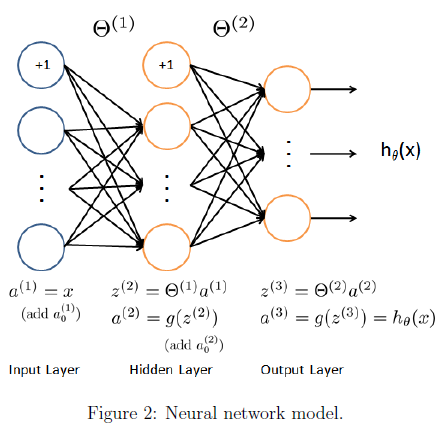

    You have been provided with a set of network parameters $(\Theta^{(1)},\Theta^{(2)})$ already trained by us. These are stored in `ex3weights.mat` and are loaded into `Theta1` and `Theta2 `by running the code below. The parameters have dimensions that are sized for a neural network with 25 units in the second layer and 10 output units (corresponding to the 10 digit classes).

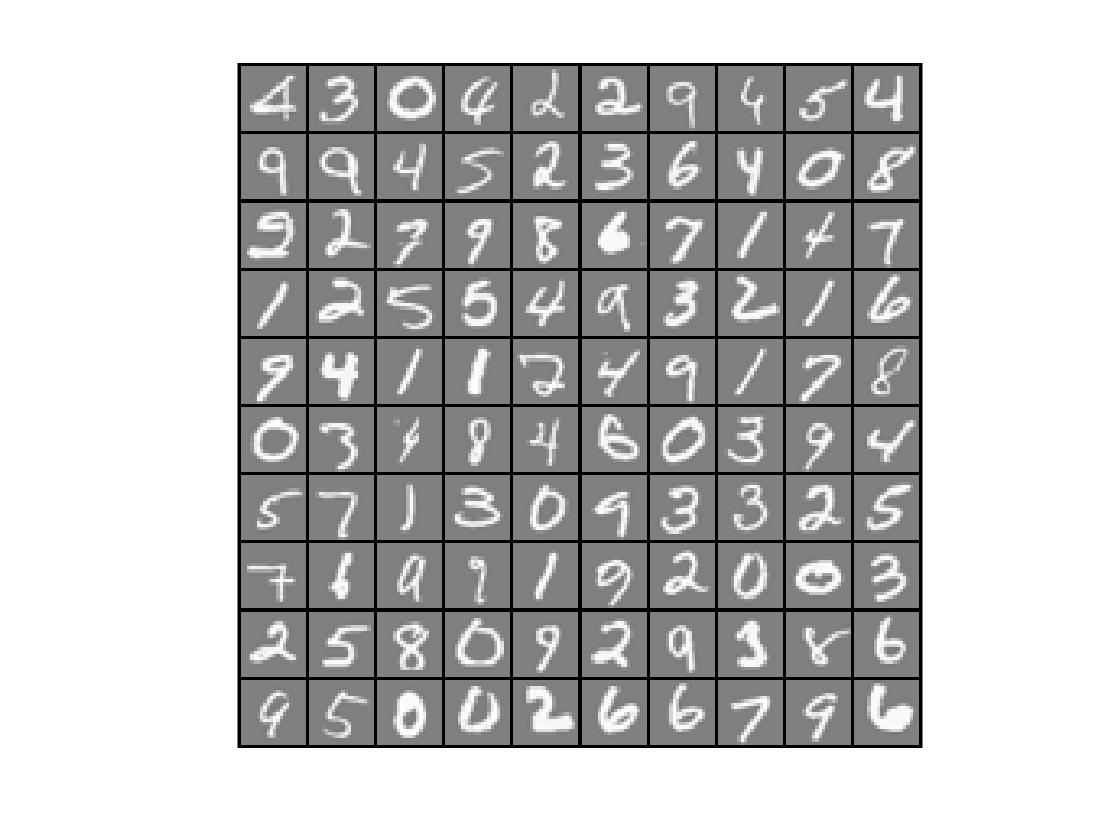

load('ex3data1.mat');
m = size(X, 1);

% Randomly select 100 data points to display
sel = randperm(size(X, 1));
sel = sel(1:100);
displayData(X(sel, :));


% Load saved matrices from file
load('ex3weights.mat'); 
% Theta1 has size 25 x 401
% Theta2 has size 10 x 26

### 2.2 Feedforward propagation and prediction

Now you will implement feedforward propagation for the neural network. You will need to complete the code in `predict.m` to return the neural network's prediction. You should implement the feedforward computation that computes $h_\theta(x^{(i)})$ for every example $i$ and returns the associated predictions. Similar to the one-vs-all classication strategy, the prediction from the neural network will be the label that has the largest output $(h_\theta(x))_k$.

**Implementation Note: **The matrix `X` contains the examples in rows. When you complete the code in `predict.m`, you will need to add the column of 1's to the matrix. The matrices `Theta1` and `Theta2` contain the parameters for each unit in rows. Specically, the first row of `Theta1` corresponds to the first hidden unit in the second layer. In MATLAB, when you compute $z^{(2)} = \Theta^{(1)}a^{(1)}$, be sure that you index (and if necessary, transpose) `X` correctly so that you get $a^{(1)}$ as a column vector.

Once you are done, run the code below to call your predict function using the loaded set of parameters for `Theta1` and `Theta2`. You should see that the accuracy is about 97.5%.

pred = predict(Theta1, Theta2, X);
fprintf('\nTraining Set Accuracy: %f\n', mean(double(pred == y)) * 100);


Training Set Accuracy: 97.520000


The code below will displaying images from the training set one at a time, while the console prints out the predicted label for the displayed image. Rerun to repeat with another image.

%  Randomly permute examples
rp = randi(m);
% Predict
pred = predict(Theta1, Theta2, X(rp,:));
fprintf('\nNeural Network Prediction: %d (digit %d)\n', pred, mod(pred, 10));


Neural Network Prediction: 9 (digit 9)


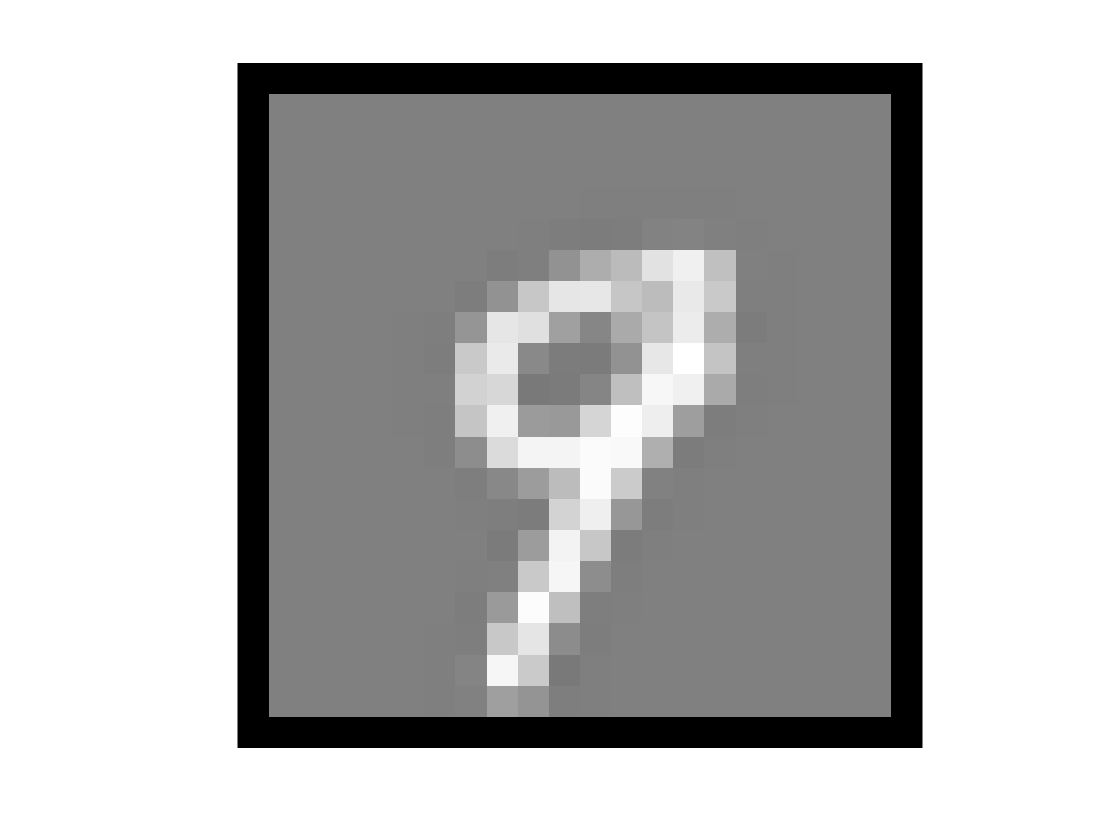

% Display 
displayData(X(rp, :));   

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

## Submission and Grading

After completing this assignment, be sure to use the submit function to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

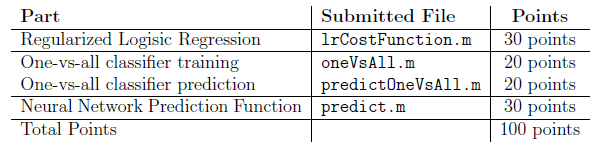

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.